# Population analysis

In this script, we load the population data and compute summary statistics and visualisations.

## Clear workspace and add repositories to path

clear all

% path_repo = fileparts(mfilename('fullpath'));
path_repo = "<YOUR_LOCAL_PATH>/Thiele-attention-gratc-LIP-pipette/repositories/attention-parietal-dopamine/analyses/";

% https://github.com/jochemvankempen/attention-parietal dopamine
addpath(genpath(fullfile(path_repo,'/../../attention-parietal-dopamine')))

% https://github.com/jochemvankempen/plotj
addpath(genpath(fullfile(path_repo,'/../../plotj')))

% https://github.com/jochemvankempen/gain-variability
addpath(genpath(fullfile(path_repo,'/../../gain-variability')))

## Directories

Set data directories

subjects = {'W','J'};

% data path, relative to repository
path_data = fullfile(path_repo,'/../../../data/processed');

path_population = regexprep(path_data,'processed','population');

if ~isfolder(path_population)
    mkdir(path_population)
end

fprintf('Load data from: %s\n', path_data)

Load data from: /Users/jochemvankempen/NCL/gratc_DA/Thiele-attention-gratc-LIP-pipette/repositories/attention-parietal-dopamine/analyses/../../../data/processed


fprintf('Save data to: %s\n', path_population)

Save data to: /Users/jochemvankempen/NCL/gratc_DA/Thiele-attention-gratc-LIP-pipette/repositories/attention-parietal-dopamine/analyses/../../../data/population


## Param

set some parameters that we'll use

label_drug = {'Dopamine','SCH23390'};
label_drug_ext = {'',' (D1-antagonist)'};
label_attention = {'Attend RF','Attend away'};
label_drug_onoff = {'Drug on','Drug off'};
label_unitclass = {'Narrow','Broad'};

markersize = 15; % scatterplot markersize

plot_conventions = 'Nature'; % follow figure conventions from this journal

% condition indices
idx_attention_cond = [1 0 0 1 0 0]; % cond_num mapping to attend RF/away in trialdata
idx_attention_roc = [1 1 0 1 1 0]; % see condition comparisons in spike_rate_ROC.m

% select units selective for task feature, e.g. attention or drug selective
% selectivity_criterium = 'none';
% selectivity_criterium = 'dru';
% selectivity_criterium = 'dru';
% selectivity_criterium = 'att';
selectivity_criterium = 'att&dru';

## Get recordinglist

Compile list of recordings from `recinfo.mat` in each session folder

recordinglist = get_recordinglist(subjects, path_data);
fprintf('Loaded %d recordings \n', height(recordinglist))

Loaded 47 recordings 


## Get population data

Compile population data matrices/tables

[rate_summary, unitlist] = get_population_data(recordinglist, 'spike_rate_summary', path_data, 'dim', 'block_change(1-Inf)');
rate_PSTH = get_population_data(recordinglist, 'spike_rate_PSTH', path_data, 'dim');
rate_ANOVA = get_population_data(recordinglist, 'spike_rate_ANOVA', path_data, 'dim');
rate_ROC = get_population_data(recordinglist, 'spike_rate_ROC', path_data, 'dim', 'block_change(1-Inf)');
waveform = get_population_data(recordinglist, 'waveform', path_data);

RT = get_population_data(recordinglist, 'RT_drug_modulation', path_data, 'stim');

## Extract param

num_rec = size(RT.RT,1);
[num_unit, num_drug, num_cond] = size(rate_summary.rate);

fprintf('Loaded %d units \n',num_unit)

Loaded 88 units 


## Classify cells as narrow or broad spiking

waveform_cutoff = 250;

unit_class = cell(num_unit,1);
unit_class(waveform.peak_to_trough_time <= waveform_cutoff) = {'Narrow'};
unit_class(waveform.peak_to_trough_time > waveform_cutoff) = {'Broad'};

% fill and define as categorical variable
unitlist.peak_to_trough_time = waveform.peak_to_trough_time;
unitlist.unit_class = categorical(unit_class, 'Ordinal', false);
unitlist.unit_class = reordercats(unitlist.unit_class, label_unitclass);

unitlist.waveform = waveform.waveform;

waveform_time = waveform.time;

clear waveform unit_class

## Append unitlist

% rename units in sequential order to be able to join to later tables
unitlist.unit = categorical((1:num_unit)', 'Ordinal', false);

% average over the ejection currents from both barrels
unitlist.EjectCurrent = nanmean(unitlist.EjectCurrent,2);
unitlist.EjectCurrent_centered = unitlist.EjectCurrent - mean(unique(unitlist.EjectCurrent));

% append/join with selectivity/ANOVA table
unitlist = join(unitlist, rate_ANOVA.selectivity, 'Keys', 'unit');

% define categorical variables
unitlist.Drug = categorical(cellstr(unitlist.Drug), 'Ordinal', false);
unitlist.Subject = categorical(cellstr(unitlist.Subject), 'Ordinal', false);

% define datetime variables
unitlist.Date = datetime(unitlist.Date, 'Format', "yyyy-MM-dd");

## Create population tables: attention

table for attention conditions, including drug on/off

% number of elements in table
t_numel = num_unit*num_drug*2;

% compute attention averages
t_rate(:,:,1) = mean(rate_summary.rate(:,:,idx_attention_cond==1),3);
t_rate(:,:,2) = mean(rate_summary.rate(:,:,idx_attention_cond==0),3);

t_FF(:,:,1) = mean(rate_summary.FF(:,:,idx_attention_cond==1),3);
t_FF(:,:,2) = mean(rate_summary.FF(:,:,idx_attention_cond==0),3);

t_PSTH(:,:,1,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==1,:),3);
t_PSTH(:,:,2,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==0,:),3);

t_gain = arrayfun(@(x)(x.rhat),rate_ROC.gv,'UniformOutput',true);
t_gain_log = log(t_gain);
t_gv = rate_ROC.gv;

% use idx_attention_roc for ROC and MI, not that this is different from the
% other attention index.
t_roc_attend(:,:,1) = mean(rate_ROC.roc_attend(:,:,idx_attention_roc==1),3);
t_roc_attend(:,:,2) = mean(rate_ROC.roc_attend(:,:,idx_attention_roc==0),3);

t_mi_attend(:,:,1) = mean(rate_ROC.mi_attend(:,:,idx_attention_roc==1),3);
t_mi_attend(:,:,2) = mean(rate_ROC.mi_attend(:,:,idx_attention_roc==0),3);

% create metadata columns
[t_att] = deal(zeros(size(t_rate)));
t_att(:,:,1) = 1;

t_unit = categorical((1:num_unit)', 'Ordinal', false);
t_unit = repmat(t_unit, [1, num_drug, 2]);

t_drug_on = [0 1];
t_drug_on = repmat(t_drug_on, [num_unit, 1, 2]);

t_unit      = reshape(t_unit, [t_numel, 1]);
t_drug_on   = reshape(t_drug_on, [t_numel, 1]);
t_att       = reshape(t_att, [t_numel, 1]);

[t_att_label,t_drug_on_label] = deal(cell(length(t_att),1));
t_att_label(t_att==1) = {'Attend RF'};
t_att_label(t_att==0) = {'Attend away'};

t_drug_on_label(t_drug_on==0) = {'Drug off'};
t_drug_on_label(t_drug_on==1) = {'Drug on'};

% reshape matrices to single columns
t_rate          = reshape(t_rate, [t_numel, 1]);
t_FF            = reshape(t_FF, [t_numel, 1]);
t_roc_attend    = reshape(t_roc_attend, [t_numel, 1]);
t_mi_attend     = reshape(t_mi_attend, [t_numel, 1]);
t_gain          = reshape(t_gain, [t_numel, 1]);
t_gain_log      = reshape(t_gain_log, [t_numel, 1]);
t_gv            = reshape(t_gv, [t_numel, 1]);

t_PSTH          = reshape(t_PSTH, [t_numel, length(rate_PSTH.time)]);

% build table
att_table = table(...
    t_unit, ...
    t_drug_on_label, t_att_label, ...
    t_rate, t_FF, ... % rate, FF
    t_roc_attend, t_mi_attend, t_gain, t_gain_log, t_gv, ... % roc, MI, gain, gain_log, GainVariability
    t_PSTH, ... % PSTH
    'VariableNames', {'unit', 'drug_on', 'attention', 'rate', 'FF', 'roc', 'MI', 'gain', 'gain_log', 'gv', 'PSTH'});

% join tables
att_table = join(att_table, unitlist, 'Keys', 'unit');

% define categorical variables
att_table.drug_on = categorical(att_table.drug_on, 'Ordinal', false);
att_table.attention = categorical(att_table.attention, 'Ordinal', false);

% reorder categories to label_* order
att_table.drug_on = reordercats(att_table.drug_on, label_drug_onoff);
att_table.attention = reordercats(att_table.attention, label_attention);

% define combined classes
att_table.attention_drug_on = att_table.attention .* att_table.drug_on;
att_table.attention_drug_on = categorical(regexprep(cellstr(att_table.attention_drug_on), ' Drug', ', Drug')); % add a comma in between classes

% clear temporary variables
clear t_*

% print head
fprintf('att_table:\n')

att_table:


disp(head(att_table))

    unit    drug_on     attention     rate       FF        roc         MI         gain      gain_log             gv                   PSTH          Subject    Task        Date         Drug      EjectCurrent    Weight    peak_to_trough_time    unit_class       waveform       EjectCurrent_centered      s_stim        s_att         s_dru         s_dir       s_att*dru    s_att*dir    s_dru*dir    s_att*dru*dir     attention_drug_on 
    ____    ________    


% save to csv file for R analysis
table_selectivity = get_unit_selectivity(att_table, selectivity_criterium);
R_table = att_table(table_selectivity,:);
R_table = removevars(R_table,{'PSTH','waveform'});
writetable(R_table, fullfile(path_population,sprintf('population_attention_%s.csv',selectivity_criterium)))

## drug table

table for analysis results that are computed for each attention condition, across drug conditions. There are thus no separate drug_on conditions in this table.

% number of elements in table
t_numel = num_unit*2;

% compute attention averages
t_roc_drug(:,1) = mean(rate_ROC.roc_drug(:,idx_attention_cond==1),2);
t_roc_drug(:,2) = mean(rate_ROC.roc_drug(:,idx_attention_cond==0),2);

t_mi_drug(:,1) = mean(rate_ROC.mi_drug(:,idx_attention_cond==1),2);
t_mi_drug(:,2) = mean(rate_ROC.mi_drug(:,idx_attention_cond==0),2);

t_roc_drug = reshape(t_roc_drug, [t_numel, 1]);
t_mi_drug = reshape(t_mi_drug, [t_numel, 1]);

% create metadata columns
t_unit = categorical((1:num_unit)', 'Ordinal', false);
t_unit = repmat(t_unit, [2, 1]);

t_cond = repmat(1:2,[num_unit 1]);

t_cond_label = cell(size(t_cond));
t_cond_label(:,1) = {'Attend RF'};
t_cond_label(:,2) = {'Attend away'};
t_cond_label = reshape(t_cond_label, [t_numel, 1]);

% build table
drug_table = table(...
    t_unit, ...
    t_cond_label, ...
    t_roc_drug, t_mi_drug, ... % roc, MI
    'VariableNames', {'unit', 'attention', 'roc', 'MI'});

% join tables
drug_table = join(drug_table, unitlist, 'Keys', 'unit');

% define categorical variables
drug_table.attention = categorical(drug_table.attention, 'Ordinal', false);

% reorder categories to label_* order
drug_table.attention = reordercats(drug_table.attention, label_attention);

% clear temporary variables
clear t_* rate_*

% print head
fprintf('drug_table:\n')

drug_table:


disp(head(drug_table))

    unit    attention      roc          MI        Subject    Task        Date         Drug      EjectCurrent    Weight    peak_to_trough_time    unit_class       waveform       EjectCurrent_centered      s_stim        s_att         s_dru         s_dir       s_att*dru    s_att*dir    s_dru*dir    s_att*dru*dir
    ____    _________    _______    __________    _______    _____    __________    ________    ____________    ______    _______________

## Print summary of data

Here we list the proportion of units that were selective for various

% all units
fprintf('UNITS\n')

UNITS


fprintf('\tRecorded %d units\n', height(unitlist))

	Recorded 88 units



% units per subject
fprintf('SUBJECTS\n')

SUBJECTS


M1 = unitlist.Subject==subjects{1};
M2 = unitlist.Subject==subjects{2};
fprintf('\tRecorded %d/%d units from monkey 1/2\n', length(find(M1)), length(find(M2)))

	Recorded 64/24 units from monkey 1/2



% unit selectivity (visual/attention)
fprintf('SELECTIVITY\n')

SELECTIVITY


unit_selectivity = get_unit_selectivity(unitlist, 'visual');
selective_visual = length(find(unit_selectivity));
fprintf('\t%d units with visual response (%1.1f%%)\n', selective_visual, selective_visual/num_unit*100)

	76 units with visual response (86.4%)


unit_selectivity = get_unit_selectivity(unitlist, 'att');
selective_attention = length(find(unit_selectivity));
fprintf('\t%d units with attentional modulation (%1.1f%%)\n', selective_attention, selective_attention/num_unit*100)

	74 units with attentional modulation (84.1%)



% units and unit selectivity per drug
fprintf('DRUG\n')

DRUG


selective_drug = 0;
selective_attdrug = 0;
selective_interaction = 0;
for idrug = 1:length(label_drug)
    
    num_drug_units = unitlist.Drug==label_drug(idrug); % total units recorded with this drug
    
    unit_selectivity = get_unit_selectivity(unitlist, 'dru',{'drug',label_drug(idrug)});
    
    fprintf('\tRecorded %d/%d (%d) units from monkey (1/2) with %s\n', length(find(M1 & num_drug_units)), length(find(M2 & num_drug_units)), length(find(num_drug_units)), label_drug{idrug})
    
    selective_drug = selective_drug+length(find(unit_selectivity));
    fprintf('\t%d units modulated by %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
    
    unit_selectivity = get_unit_selectivity(unitlist, 'att&dru',{'drug',label_drug(idrug)});
    selective_attdrug = selective_attdrug+length(find(unit_selectivity));
    fprintf('\t%d units modulated by attention and drug %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
    
    unit_selectivity = get_unit_selectivity(unitlist, 'att*dru',{'drug',label_drug(idrug)});
    selective_interaction = selective_interaction+length(find(unit_selectivity));
    fprintf('\t%d units interaction with attention %s (%1.1f%%)\n', length(find(unit_selectivity)), label_drug{idrug}, length(find(unit_selectivity))/length(find(num_drug_units))*100)
end

	Recorded 41/18 (59) units from monkey (1/2) with Dopamine


	36 units modulated by Dopamine (61.0%)


	31 units modulated by attention and drug Dopamine (52.5%)


	4 units interaction with attention Dopamine (6.8%)


	Recorded 23/6 (29) units from monkey (1/2) with SCH23390


	14 units modulated by SCH23390 (48.3%)


	14 units modulated by attention and drug SCH23390 (48.3%)


	5 units interaction with attention SCH23390 (17.2%)



% unit summary
fprintf('SUMMARY\n')

SUMMARY


fprintf('\t%d total units modulated by attention  (%1.1f%%)\n', selective_attention, selective_attention/num_unit*100)

	74 total units modulated by attention  (84.1%)


fprintf('\t%d total units modulated by drug application  (%1.1f%%)\n', selective_drug, selective_drug/num_unit*100)

	50 total units modulated by drug application  (56.8%)


fprintf('\t%d total units modulated by drug application and attention  (%1.1f%%)\n', selective_attdrug, selective_attdrug/num_unit*100)

	45 total units modulated by drug application and attention  (51.1%)


fprintf('\t%d total units interaction attention by drug application  (%1.1f%%)\n', selective_interaction, selective_interaction/num_unit*100)

	9 total units interaction attention by drug application  (10.2%)


%

## Plot population histogram and example unit

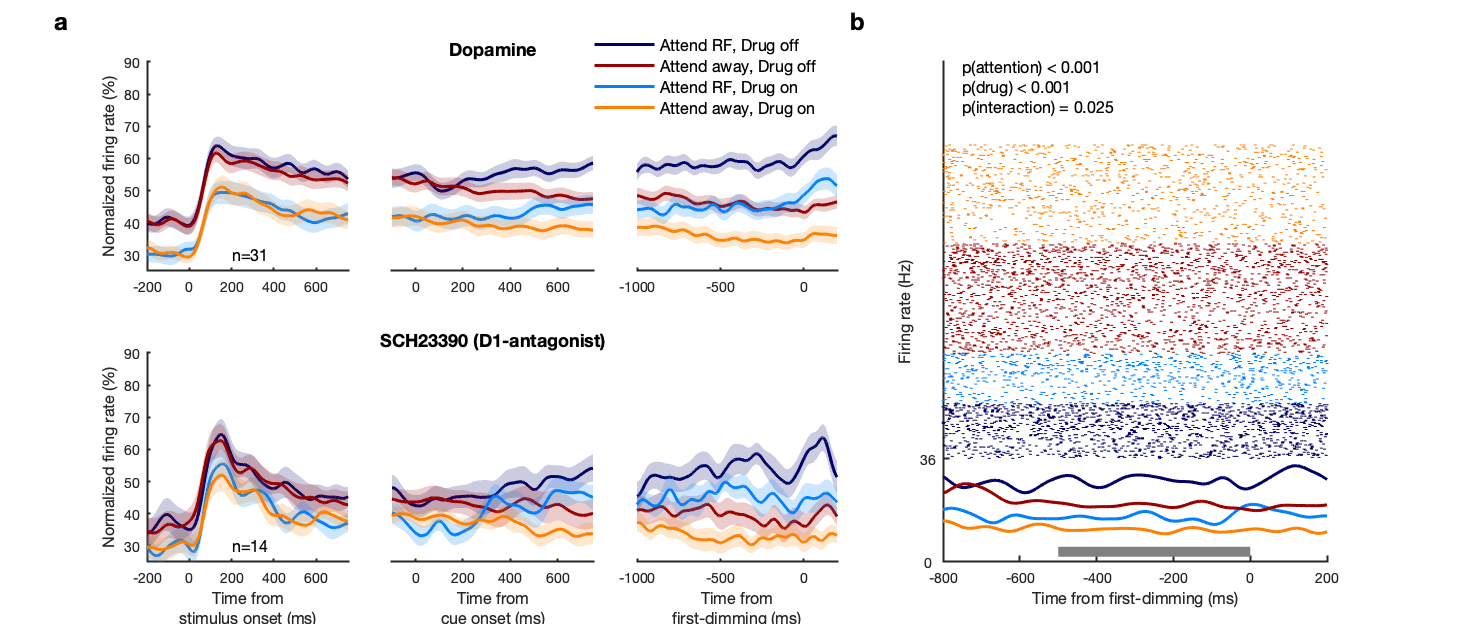

[colors, labels] = get_colors('att_drug');
colors = reshape(colors, [4,3]);
labels = reshape(labels, [4,1]);

linestyle = {'-','-','-','-'};

events = {'stim', 'cue', 'dim'};
label_event = {'Stimulus onset', 'Cue onset', 'First-dimming'};
xlabel_event = {{'Time from','stimulus onset (ms)'}, {'Time from','cue onset (ms)'}, {'Time from','first-dimming (ms)'}};
xlim2use = {[-200 750], [-100 750], [-1000 200]};
ylim2use = [25 90];
ncol = length(label_event) + 2;
nrow = length(label_drug);

idx_subplot = {1,2,3,6,7,8,[4 5 9 10]};

[fH, fSet] = plotj_initFig('width', 26, 'height', 11, 'Journal',plot_conventions);
fSet.subplotGap2 = fSet.subplotGap .* [1.3 0.30];

iplot = 0;
for irow = 1:nrow
    
    idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(irow)});
    
    clear h
    for ievent = 1:length(label_event)
        iplot = iplot+1;
        
        rate_PSTH = get_population_data(recordinglist, 'spike_rate_PSTH', path_data, events{ievent});
        
        times = rate_PSTH.time;
        
        % convert samples to att_table format
        t_numel = num_unit*num_drug*2;
        clear t_PSTH
        t_PSTH(:,:,1,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==1,:),3);
        t_PSTH(:,:,2,:) = mean(rate_PSTH.samples(:,:,idx_attention_cond==0,:),3);
        t_PSTH          = reshape(t_PSTH, [t_numel, length(times)]);
        
        % initialise axes
        subtightplot(nrow, ncol, idx_subplot{iplot}, fSet.subplotGap2, fSet.subplotMargin, fSet.subplotMargin)
        if ievent==1 && irow==1
            plotj_initAx(fSet, 'axlabel', irow, 'axlabelDisplacement', [0.07, 0.00]);
        else
            plotj_initAx(fSet);
        end
        
        if ievent==(ceil(length(label_event)/2))
            ht = title([label_drug{irow} label_drug_ext{irow}], 'FontSize', fSet.Fontsize_title);
            %             ht.Position = ht.Position + [0.05 0 0];
        end
        if (ievent~=1)
            axh = get(gca);
            axh.YTick = [];
            axh.YAxis.Visible = 'off'; % remove y-axis
            %             axes('Color','none','YColor','none')
            %             set(gca,'xtick',[])
        end
        hold on
        
        % plot each attention and drug condition
        icol = 0;
        conditions = categories(att_table.attention_drug_on);
        for iatt_drug = 1:length(conditions)
            
            idx_att_drug = att_table.attention_drug_on==labels{iatt_drug};
            
            idx = idx_unit & idx_att_drug;
            
            icol = icol+1;
            h(icol) = boundedline(times, ...
                squeeze(mean(t_PSTH(idx,:),1)), ...
                squeeze(std(t_PSTH(idx,:),[],1))/sqrt(length(find(idx))), ...
                'cmap', colors(iatt_drug,:), 'alpha');
            set(h(icol), 'LineWidth', fSet.LineWidth)
            set(h(icol), 'LineStyle', linestyle{iatt_drug})
            
        end
        xlim(xlim2use{ievent})
        ylim(ylim2use)
        
        if ievent==1
            ylabel('Normalized firing rate (%)', 'FontSize', fSet.Fontsize_text)
            
            text(200, 30, sprintf('n=%d', length(find(idx))))
        elseif ievent==3
            if 0%irow==1
                hleg = legend(h, labels, 'FontSize', fSet.Fontsize_text, 'Box', 'Off');
                hleg.Position = hleg.Position + [0.05 0.15 0 0];
            end
        end
        
        if irow==nrow
            xlabel(xlabel_event{ievent}, 'FontSize', fSet.Fontsize_text)
        end
    end
    
    
end
hleg = legend(h, labels, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'Location', 'NorthWest');
hleg.Position = hleg.Position + [-0.04 0.53 0 0];


% plot example cell, plot raster for example cell, only drug/attention

% plot param
iplot = iplot+1;
axH = subtightplot(nrow, ncol, idx_subplot{iplot}, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
hold on
plotj_initAx(fSet, 'axlabel', 2, 'axlabelDisplacement', [0.07, 0.00]);
yoffset = 100;

[colors] = get_colors('att_drug');

% load data for single unit
event2plot = 3;
rec2plot = {'W','2015-10-01'};
unit2plot = [41 1];

idx_unit = unitlist.Subject==rec2plot{1} ...
    & unitlist.Date==rec2plot{2} ...
    & unitlist.unit==categorical(unit2plot(1));

loadfilename = fullfile(path_data, string(unitlist.Subject(idx_unit)), string(unitlist.Date(idx_unit)), 'unit.mat');
unit = load(loadfilename);
loadfilename = fullfile(path_data, string(unitlist.Subject(idx_unit)), string(unitlist.Date(idx_unit)), 'trialdata.mat');
load(loadfilename);
% [trialdata, unit] = remove_excluded_trials(trialdata, unit, unit2plot);

% select only trial window for which this unit has spikes
sps = unit.Dim1Align;

% raster for each condition
idx_attend = idx_attention_cond([trialdata.cond_num])';
idx_drug = [trialdata.drug]' + 1;
ymax = 0;
icond = 0;
for iatt = 1:length(unique(idx_attention_cond))
    for idrug = 1:2
        icond = icond+1;
        
        % get trial indices
        trial_index = (...
            idx_drug==idrug) ...
            & abs(idx_attend-2)==iatt;
        
        % compute raster
        [xspikes, yspikes] = spike_raster( sps(:,trial_index), xlim2use{event2plot}, unit2plot(2));
        
        % get PSTH
        x = rate_PSTH.time;
        y = squeeze(mean(rate_PSTH.samples(idx_unit,idrug,abs(idx_attention_cond-2)==iatt,:),3));
        
        % plot
        h(icol) = plot(x, y, 'Color', colors(iatt,idrug,:), 'linew', fSet.LineWidth, 'LineStyle', linestyle{icond});
        plot(xspikes, yspikes+yoffset+ymax, 'Color', colors(iatt,idrug,:), 'linew', 1.5)
        
        % set y-offset for next iteration
        ymax = ymax + max(yspikes(:));
    end
end
plot([-500 0], [10 10], 'Color', [0.5 0.5 0.5], 'linew', 5)
set(gca,'YTick',[0 yoffset],'YTicklabel',[0 round(rate_PSTH.maxhist(idx_unit)*1000)]);
xlabel('Time from first-dimming (ms)', 'FontSize', fSet.Fontsize_text)
ylabel('Firing rate (Hz)', 'FontSize', fSet.Fontsize_text)

xlim([-800 200])
ylim2use = yoffset+ymax+80;
ylim([0 ylim2use])

% set text in plot
p = [unitlist.s_att(idx_unit) unitlist.s_dru(idx_unit) unitlist.("s_att*dru")(idx_unit)];
[pstring,starstring] = get_significance_strings(p, 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
text(axH, -750, ylim2use*0.95, pstring, 'FontSize', fSet.Fontsize_text)

## Violin population plots, mean-var relationship, auroc

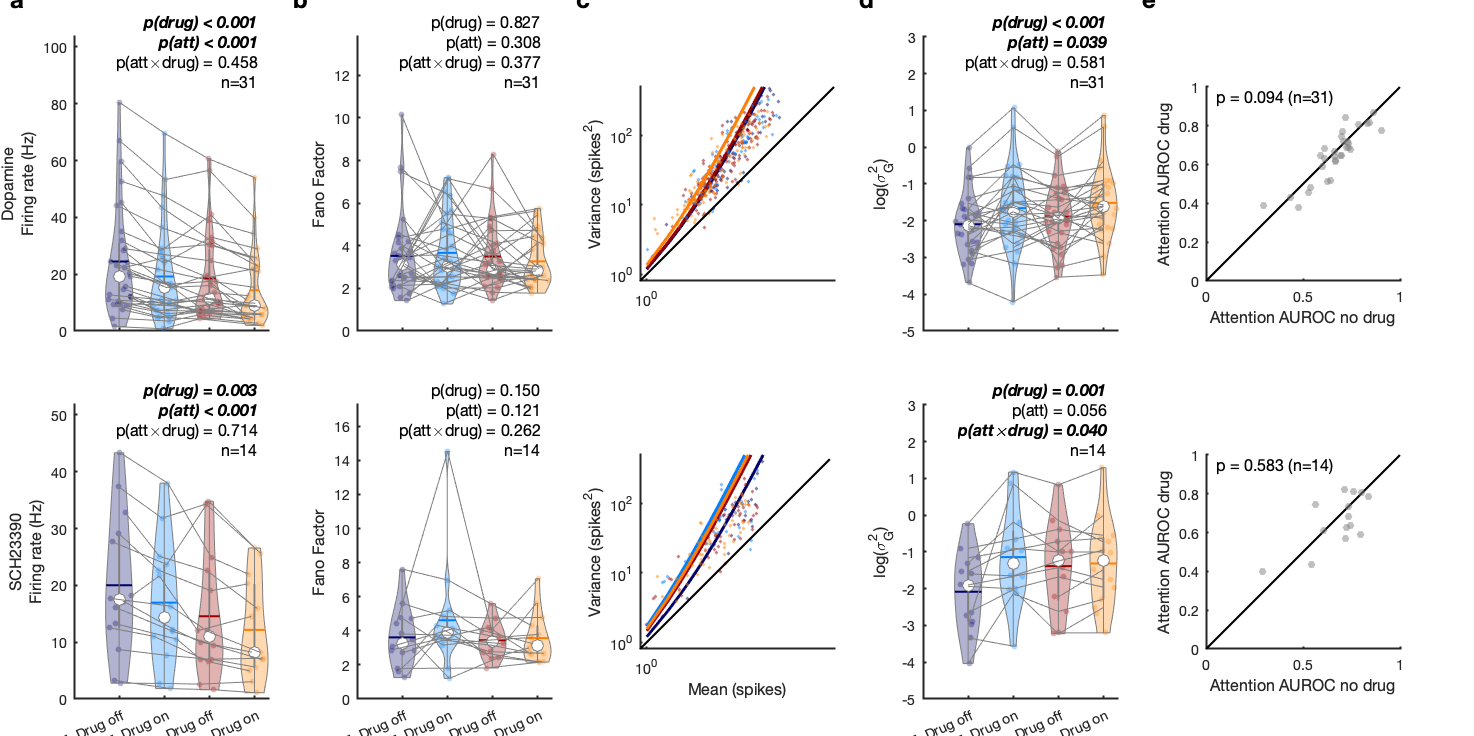

Testing model: Dopamine 


	 Found 31 units 


Linear mixed-effects model fit by ML

Model information:
    Number of observations             124
    Fixed effects coefficients           4
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    rate ~ 1 + drug_on*attention + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    848.12    865.04    -418.06          836.12  

Fixed effects coefficients (95% CIs):
    Name                                           Estimate    SE         tStat       DF     pValue        Lower      Upper  
    {'(Intercept)'                        }         19.132      2.7502      6.9564    120    1.9744e-10     13.687     24.577
    {'drug_on_Drug on'                    }        -2.3639     0.38775     -6.0964    120    1.3585e-08    -3.1316    -1.5962
    {'attention_Attend RF'                }         2.6939     0.38775      6.9476    120 

AUROC: Dopamine, delta-AUROC -0.02 +- 0.01, p = 0.094, Cohens's d = -0.28


Testing model: SCH23390 


	 Found 14 units 


Linear mixed-effects model fit by ML

Model information:
    Number of observations              56
    Fixed effects coefficients           4
    Random effects coefficients         14
    Covariance parameters                2

Formula:
    rate ~ 1 + drug_on*attention + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    355.56    367.71    -171.78          343.56  

Fixed effects coefficients (95% CIs):
    Name                                           Estimate    SE         tStat       DF    pValue        Lower      Upper   
    {'(Intercept)'                        }          15.922     2.6476       6.014    52    1.8299e-07      10.61      21.235
    {'drug_on_Drug on'                    }         -1.3651    0.44484     -3.0688    52     0.0034106    -2.2578    -0.47248
    {'attention_Attend RF'                }          2.5624    0.44484      5.7602    52  

AUROC: SCH23390, delta-AUROC -0.02 +- 0.03, p = 0.583, Cohens's d = -0.20


data2plot = {'rate','FF','gain_log'};

colors = get_colors('spikewidth');
markerstyle = {'o','o'};

[colors_violin, labels_violin] = get_colors('att_drug');
colors_violin = reshape(colors_violin, [4,3]);
labels_violin = reshape(labels_violin, [4,1]);

% plotting param
ncol = length(data2plot) + 1 + 1; % 
nrow = 2; % drugs
iplot = 0;
plotlabel_offset = 0;
xval_gain = 1:500;

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 26, 'height', 13, 'Journal',plot_conventions);
fSet.subplotGap = [0.1, 0.06];
fSet.subplotMargin = fSet.subplotMargin / 2;
for idrug = 1:num_drug

    fprintf('Testing model: %s \n', label_drug{idrug})
    
    idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
    num_unit_plot = length(unique(att_table.unit(idx_unit)));
    fprintf('\t Found %d units \n',  num_unit_plot)
    
    for idp = 1:length(data2plot)
        
        % plot violinplot
        iplot = iplot+1;
        
        % init axes
        subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
        if idrug==1
            axH = plotj_initAx(fSet, 'axlabel', iplot + plotlabel_offset, 'axlabelDisplacement', [0.05, 0.02]);
        else
            axH = plotj_initAx(fSet);
        end
        hold on
        
        % extract smaller table
        %         v_att_table = unstack(att_table(idx_unit,:), data2plot{idp}, {'attention_drug_on'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        v_att_table = att_table(idx_unit, ismember(att_table.Properties.VariableNames, {data2plot{idp},'drug_on','attention','unit','attention_drug_on'}));
        
        switch data2plot{idp}
            case {'gain_log', 'gain'}
                
                gv = unstack(att_table(idx_unit,:), 'gv', {'attention_drug_on'}, 'GroupingVariables', {'unit'}, 'VariableNamingRule', 'preserve');
                variable_names = gv.Properties.VariableNames;
                
                for iatt_drug = 1:length(labels_violin)
                    
                    mus = [gv.(labels_violin{iatt_drug}).mus];
                    s2s = [gv.(labels_violin{iatt_drug}).s2s];
                    
                    mus = mus(:);
                    s2s = s2s(:);
                    
                    % get binomial fit
                    rhat = nanmean([gv.(labels_violin{iatt_drug}).rhat]);
                    
                    gv_pop = GainVariability;
                    gv_pop.rhat = rhat;
                    m2v = gv_pop.pred_variance(xval_gain);
                    
                    % plot
                    scatter(mus, s2s, fSet.MarkerSize, colors_violin(iatt_drug,:), 'filled', 'MarkerFaceAlpha', 0.5);
                    
                    plot(m2v.mean, m2v.variance,'Color', colors_violin(iatt_drug,:), 'linew', fSet.LineWidth);
                    xlim([0.8 max(xval_gain)])
                    ylim([0.8 max(xval_gain)])
                    plot([1e-10 max(s2s)*1.1],[1e-10 max(s2s)*1.1],'k','linew',1)
                    set(gca,'xscale','log','yscale','log')
                end
                %         axis square
                %     legend(h(:),labels(:),'Location','SouthEast','Fontsize',fSet.Fontsize_text)
                
                if idrug==length(label_drug)
                    xlabel('Mean (spikes)','FontSize',fSet.Fontsize_text)
                end
                ylabel('Variance (spikes^{2})','FontSize',fSet.Fontsize_text)
                axis square
                
                iplot = iplot+1;
                subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
                if idrug==1
                    axH = plotj_initAx(fSet, 'axlabel', iplot + plotlabel_offset, 'axlabelDisplacement', [0.05, 0.02]);
                else
                    axH = plotj_initAx(fSet);
                end
                hold on
        end
        
        % plot violin
        v = violinplot(v_att_table.(data2plot{idp}), v_att_table.attention_drug_on, 'ShowMean', true);
        XTickLabel = get(gca,'XTickLabel');
        for iv = 1:length(v)
            v(iv).ScatterPlot.SizeData = 10;
            idx = strcmpi(XTickLabel(iv), labels_violin);
            v(iv).ViolinColor = colors_violin(idx,:);
        end
        
        % plot lines for each unit
        [data_x, data_y] = deal(NaN(num_unit_plot, length(length(v))));
        for iv = 1:length(v)
            %             data_x(:,iv) = v(iv).ScatterPlot.XData;
            %             data_y(:,iv) = v(iv).ScatterPlot.YData;
            
            
            if ~any(isnan(v_att_table.(data2plot{idp})))
                % works if data is complete
                data_x(:,iv) = v(iv).ScatterPlot.XData;
                data_y(:,iv) = v(iv).ScatterPlot.YData;
            else
                % catch if nan values are present
                idx = strcmpi(XTickLabel(iv), labels_violin);
                
                idx_trial = v_att_table.attention_drug_on==labels_violin{idx};
                data_x(:,iv) = iv;
                data_y(:,iv) = v_att_table.(data2plot{idp})(idx_trial);
            end
        end
        plot(data_x', data_y', 'Color', [0.5 0.5 0.5 0.3]);
        
        % fit model
        lme_population = fitlme(v_att_table,[data2plot{idp} ' ~ 1 + attention*drug_on + (1|unit)'],'DummyVarCoding','effects'); % fit interaction model with effect coding
        disp(lme_population)
        
        coefficients = lme_population.Coefficients;
        
        betas = coefficients.Estimate(2:end);
        betas_se = coefficients.SE(2:end);
        p_val = coefficients.pValue(2:end);
        
        %         p_string = get_significance_strings(p_val, 'rounded', 0);
        p_string = get_significance_strings(p_val, 'rounded', 0, 'factorstring', {'drug','att',sprintf('att%sdrug', '\times')});
        p_string{end+1} = sprintf('n=%d',num_unit_plot);
        %         % full betastring: Estimate, SE, p-value
        %         betastring = {...
        %             sprintf('drug: %s = %1.2f%s%1.2f, %s', '\beta', betas(1), '\pm', betas_se(1), p_string{1}), ...
        %             sprintf('att: %s = %1.2f%s%1.2f, %s', '\beta', betas(2), '\pm', betas_se(2), p_string{2}), ...
        %             sprintf('att %s drug: %s = %1.2f%s%1.2f, %s', '\times', '\beta', betas(3), '\pm', betas_se(3), p_string{3}), ...
        %             sprintf('n = %d',length(unique(v_att_table.unit)))};
        
        %         % part betastring: Estimate, SE, p-value
        %         betastring = {...
        %             sprintf('drug: %s = %1.2f, %s', '\beta', betas(1), p_string{1}), ...
        %             sprintf('att: %s = %1.2f, %s', '\beta', betas(2), p_string{2}), ...
        %             sprintf('att %s drug: %s = %1.2f, %s', '\times', '\beta', betas(3), p_string{3}), ...
        %             sprintf('n = %d',length(unique(v_att_table.unit)))};
        
        % plot text
        YLIM = get(gca,'ylim');
        switch data2plot{idp}
            case {'gain_log', 'gain'}
                set(gca, 'ylim', YLIM .* [1 1.5])
            otherwise
                set(gca, 'ylim', YLIM .* [1 1.15])
        end
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.95);
        y_pos = get_value_range(tmp_y, 0.95);
        
        h_text = text(x_pos, y_pos, p_string,'HorizontalAlignment','right', 'FontSize', fSet.Fontsize_text);
        
        [p_masked] = p_val<0.05;
        p_masked = [p_masked ; false];
        plotj_text_emphasise(h_text, 1, 'italic', p_masked);
        plotj_text_emphasise(h_text, 1, 'bold', p_masked);
        
        switch data2plot{idp}
            case 'rate'
                if idp==1
                    ylabel({label_drug{idrug}, 'Firing rate (Hz)'}, 'FontSize', fSet.Fontsize_text)
                else
                    ylabel('Firing rate (Hz)', 'FontSize', fSet.Fontsize_text)
                end
            case 'FF'
                ylabel('Fano Factor', 'FontSize', fSet.Fontsize_text)
            case 'gain'
                ylabel('\sigma_{G}^{2}', 'FontSize', fSet.Fontsize_text)
            case 'gain_log'
                ylabel('log(\sigma_{G}^{2})', 'FontSize', fSet.Fontsize_text)
        end
        
        
        if idrug == 2
            set(gca,'XTickLabelRotation',25)
        else
            set(gca, 'XTickLabel', '')
        end
    end
    
    
    % attention/drug auroc
    iplot = iplot+1;
    
    % init axes
    subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
    if idrug==1
        axH = plotj_initAx(fSet, 'axlabel', iplot + plotlabel_offset, 'axlabelDisplacement', [0.05, 0.02]);
    else
        axH = plotj_initAx(fSet);
    end
    hold on
    
    % get data - AUROC
    idx_cond = att_table.attention=='Attend RF';
    
    idx = idx_unit & idx_cond;
    tmp_data = zeros(length(find(idx))/2,1);
    tmp_data(:,1) = att_table.roc(idx & att_table.drug_on=='Drug off');
    tmp_data(:,2) = att_table.roc(idx & att_table.drug_on=='Drug on');
    
    plotj_scatter(tmp_data, ...
        'markerStyle', markerstyle, 'MarkerSize', markersize, ...
        'markerFaceColor', [0.5 0.5 0.5], 'markerFaceAlpha', 0.5, ...
        'markerEdgeColor', [0.5 0.5 0.5], 'markerEdgeAlpha', 0.5, ...
        'axislimit', [0 1]);
    % stats
    P(idrug) = compare_means(tmp_data(:,1),tmp_data(:,2), 1, 'rank');
    
    axis square
    p_string = get_significance_strings(P(idrug), 'rounded', 0);
    
    % mean difference
    delta_data = tmp_data(:,2)-tmp_data(:,1);
    
    % effect size
    d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
    
    % print result
    fprintf('%s: %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
        'AUROC', ...
        label_drug{idrug}, ...
        'AUROC', ...
        mean(delta_data), ...
        std(delta_data)/sqrt(size(tmp_data,1)), ...
        p_string, ...
        d)
    
    % set text
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.05);
    y_pos = get_value_range(tmp_y, 0.95);
    
    h_text(idrug) = text(x_pos, y_pos, ...
        sprintf('%s (n=%d)', p_string, size(tmp_data,1)), ...
        'FontSize', fSet.Fontsize_text);
    
    xlabel('Attention AUROC no drug','FontSize', fSet.Fontsize_text)
    ylabel('Attention AUROC drug','FontSize', fSet.Fontsize_text)
    
    
end

## Post hoc comparisons: scatter plots and signed-rank tests

plotting and post-hoc tests

ncol = 2 * (length(label_drug));
nrow = 3; % 

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 20, 'height', 12, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

[P, h_text] = deal( NaN(length(label_drug), nrow, 2, 2) ); % drugtype, actvity-type, attention, drug-offon,
    
iplot=0;
for irow = 1:3
    
    if irow == 1
        % mean rate
        datatype = 'rate';
        ylim2use = [0.7 100];
        
        scale ='Log';
        x_text = 0.005;
        y_text = [0.9];
    elseif irow == 2
        % Fano factor
        datatype = 'FF';
        ylim2use = [0 10];
        
        scale ='Linear';
        x_text = 0.1;
        y_text = [0.95];
    elseif irow == 3
        % gain variability
        datatype = 'gain_log';
        ylim2use = [-4 2];
        
        scale ='Linear';
        x_text = 0.1;
        y_text = [0.9];
    end
    
    data2plot = att_table.(datatype);
    
    for idrug = 1:length(label_drug)
        
        for iatt = 1:2
            iplot = iplot+1;
            
            subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
            axH = plotj_initAx(fSet, 'axlabelDisplacement', [0.05, 0.02]);
            hold on
            
            if irow==1 && iatt==1
                % sup-title
                set(gca,'units','normalized')
                text(100, 400, ['\bf ' label_drug{idrug}], 'FontSize', fSet.Fontsize_title, 'Interpreter', 'tex')
            end
            
            
            if (irow==1)
                title(sprintf('%s', label_attention{iatt}), 'FontSize', fSet.Fontsize_title)
            end
            
            % unit selection
            idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
            idx_att = att_table.attention == label_attention{iatt};
            
            unit2plot = idx_unit ...
                & idx_att;
            
            % extract data
            tmp_data = [data2plot(unit2plot & att_table.drug_on==label_drug_onoff{1}) ...
                data2plot(unit2plot & att_table.drug_on==label_drug_onoff{2})];
            
            
            plotj_scatter(tmp_data, ...
                'MarkerSize', markersize, ...
                'markerFaceColor', fSet.colors(1,:), 'markerFaceAlpha', 0.5, ...
                'axislimit', ylim2use);
            
            % stats
            P(idrug,irow,iatt) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
            
            % effect size
            d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
            
            % mean difference
            delta_data = tmp_data(:,2)-tmp_data(:,1);
            
            axis square
            p_string = get_significance_strings(P(idrug,irow,iatt), 'rounded', 0);
            
            % print result
            fprintf('%s: %s, attend %s: delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
                datatype, ...
                label_drug{idrug}, ...
                label_attention{iatt}, ...
                datatype, ...
                nanmean(delta_data), ...
                nanstd(delta_data)/sqrt(length(tmp_data)), ...
                p_string, ...
                d)
            
            % plot text
            tmp_x = get(gca,'xlim');
            tmp_y = get(gca,'ylim');
            
            x_pos = get_value_range(tmp_x, x_text);
            y_pos = get_value_range(tmp_y, y_text);
            
            h_text(idrug,irow,iatt) = text(x_pos, y_pos, ...
                sprintf('%s', p_string), ...
                'Color', fSet.colors(1,:));
            
            if iatt==2
                
                x_pos = get_value_range(tmp_x, 0.6);
                y_pos = get_value_range(tmp_y, 0.2);
                
                text(x_pos, y_pos, sprintf('(n=%d)', length(tmp_data)), 'Color', fSet.colors(1,:));
            end
            
            
            xlim(ylim2use)
            ylim(ylim2use)
            set(gca,'YScale', scale, 'XScale', scale)
            % %     set(gca,'', [1 10 100])
            
            if irow == 1
                set(gca,'Xtick', [1 10 100], 'XTickLabel', [1 10 100])
                set(gca,'Ytick', [1 10 100], 'YTickLabel', [1 10 100])
                
                xlabel('Firing rate no drug (Hz)','FontSize', fSet.Fontsize_text)
                
                if idrug==1 && iatt==1
                    ylabel('Firing rate drug (Hz)','FontSize', fSet.Fontsize_text)
                end
            elseif irow == 2
                xlabel('Fano Factor no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Fano Factor drug','FontSize', fSet.Fontsize_text)
                end
            elseif irow == 3
                xlabel('Gain variability no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Gain variability drug','FontSize', fSet.Fontsize_text)
                end
            end
        end
    end
    
end

rate: Dopamine, attend Attend RF: delta-rate 5.30 +- 0.87, p < 0.001, Cohens's d = 1.09
rate: Dopamine, attend Attend away: delta-rate 4.15 +- 0.84, p < 0.001, Cohens's d = 0.88
rate: SCH23390, attend Attend RF: delta-rate 3.06 +- 0.80, p = 0.002, Cohens's d = 1.03
rate: SCH23390, attend Attend away: delta-rate 2.40 +- 0.91, p = 0.017, Cohens's d = 0.71
FF: Dopamine, attend Attend RF: delta-FF -0.14 +- 0.36, p = 0.779, Cohens's d = -0.07
FF: Dopamine, attend Attend away: delta-FF 0.23 +- 0.21, p = 0.504, Cohens's d = 0.20
FF: SCH23390, attend Attend RF: delta-FF -1.00 +- 0.79, p = 0.296, Cohens's d = -0.34
FF: SCH23390, attend Attend away: delta-FF -0.13 +- 0.33, p = 0.903, Cohens's d = -0.10
gain_log: Dopamine, attend Attend RF: delta-gain_log -0.46 +- 0.14, p = 0.006, Cohens's d = -0.57
gain_log: Dopamine, attend Attend away: delta-gain_log -0.34 +- 0.11, p = 0.006, Cohens's d = -0.59
gain_log: SCH23390, attend Attend RF: delta-gain_log -0.82 +- 0.31, p = 0.009, Cohens's d = -0.82
ga

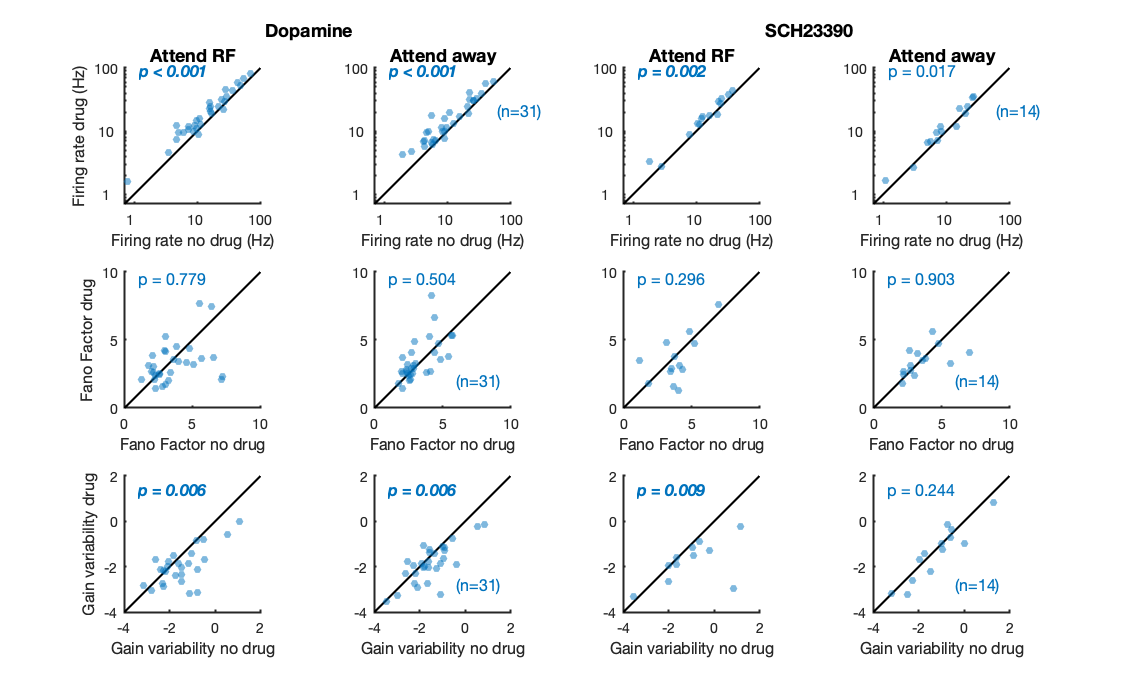


[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');

## plot histogram cell-widths

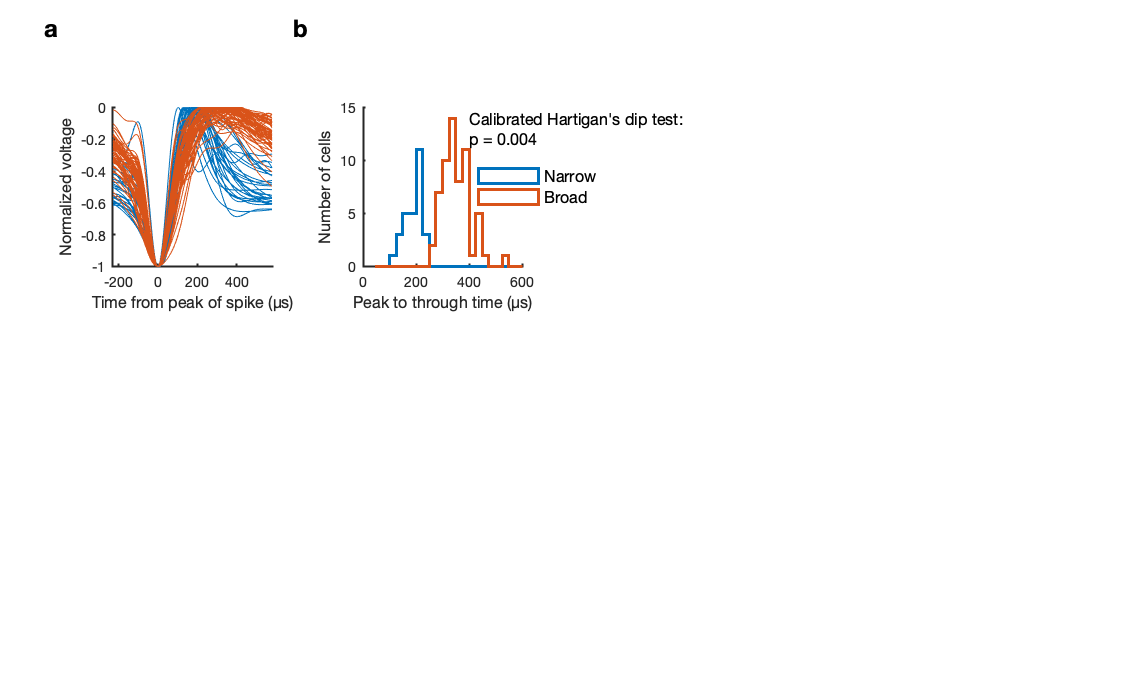

colors = get_colors('spikewidth');

binsize = 25;
binedges = 50:binsize:600;

assert(any(ismember(binedges,waveform_cutoff)), 'threshold needs to be included in binedges')

[fH, fSet] = plotj_initFig('width', 20, 'height', 12, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

ncol=4;
nrow=2;

subtightplot(nrow, ncol, 1, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
plotj_initAx(fSet, 'axlabel', 1, 'axlabelDisplacement', [0.07, 0.01]);
hold on

x = waveform_time-(7*6*5.4);
plot(x, unitlist.waveform(unitlist.unit_class=='Narrow',:)*-1, 'Color', [colors(1,:) 0.5])
plot(x, unitlist.waveform(unitlist.unit_class=='Broad',:)*-1, 'Color', [colors(2,:) 0.5])

xlabel(['Time from peak of spike (' plotj_symbol('mu') 's)'], 'FontSize', fSet.Fontsize_text)
ylabel(['Normalized voltage'], 'FontSize', fSet.Fontsize_text)

xlim(minmax(waveform_time)+[0 -200]-7*6*5.4)
axis square

subtightplot(nrow, ncol, 2, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
plotj_initAx(fSet, 'axlabel', 2, 'axlabelDisplacement', [0.07, 0.01]);
hold on

h = plotj_hist({unitlist.peak_to_trough_time(unitlist.unit_class=='Narrow'), unitlist.peak_to_trough_time(unitlist.unit_class=='Broad')}, ...
    'bins', binedges, ...
    'EdgeColor', colors, ...
    'histstyle', 'stairs',...
    'plotmean', 0, ...
    'LineWidth', fSet.LineWidth);

xlabel(['Peak to through time (' char(181) 's)'], 'FontSize', fSet.Fontsize_text)
ylabel('Number of cells', 'FontSize', fSet.Fontsize_text)
axis square

hleg = legend(h, {'Narrow','Broad'}, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'AutoUpdate', 'Off', 'Location', 'East');
hleg.Position = hleg.Position + [0.08 0 0 0];

% do hartigan's dip test to see whether there is a significant dip in this
% distribution
% [dip, p_value, xlow,xup]=HartigansDipSignifTest(allSpikeWaveform.width(idx_unit),5000);
[dip, p_value, xlow, xup, boot_dip]=CalibratedHartigansDipSignifTest(unitlist.peak_to_trough_time, 10000);


p_string = get_significance_strings(p_value, 'round', 0);
h_text(1) = text(400, 13, {'Calibrated Hartigan''s dip test:', p_string}, 'FontSize', fSet.Fontsize_text);

%

## LME model fit

model fit to 'rate', 'FF' and 'gain' across attention and drug conditions, for broad and narrow spiking cells. We use random intercepts for each unit to account for the repeated measures

% Note these excellent explanations of effect coded predictors:
% - https://stats.idre.ucla.edu/other/mult-pkg/faq/general/faq-how-do-i-interpret-the-coefficients-of-an-effect-coded-variable-involved-in-an-interaction-in-a-regression-model/#effect-coded-predictors-interacted-with-a-continuous-covariate
% - https://stats.idre.ucla.edu/other/mult-pkg/faq/general/faqwhat-is-effect-coding/

data2plot = {'rate', 'FF', 'gain_log'};

for idrug = 1:num_drug
    
    idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
    
    tmp_table = att_table(idx_unit,:);
    
    for idp = 1:length(data2plot)
        
        fprintf('\nDRUG: %s, DATATYPE: %s, UNIT SELECTION: %s, n=%d \n', label_drug{idrug}, data2plot{idp}, selectivity_criterium, length(unique(att_table.unit(idx_unit))))
        
        % model fit across attention, drug and unit_class
        mod_population.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention*drug_on*unit_class + (1|unit)'],'DummyVarCoding','effects'); % fit interaction model with effect coding
        mod_population.anova = anova(mod_population.lme);
        
        %         % hierarchical model fits
        %         mod.m1_intercept.lme = fitlme(tmp_table,[data2plot{idp} ' ~ 1 + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m2_att.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m3_drug.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m4_unitc.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + unit_class + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m5_att_drug.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + unit_class + attention*drug_on + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m6_att_unitc.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + unit_class + attention:drug_on + attention:unit_class + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m7_drug_unitc.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + unit_class + attention:drug_on + attention:unit_class + drug_on:unit_class + (1|unit)'],'DummyVarCoding','effects');
        %         mod.m8_att_drug_unitc.lme = fitlme(tmp_table,[data2plot{idp} ' ~ attention + drug_on + unit_class + attention:drug_on + attention:unit_class + drug_on:unit_class + attention:drug_on:unit_class + (1|unit)'],'DummyVarCoding','effects');
        %
        %         % likelihood ratio tests of hierarchical model fits
        %         mod.m2_att.compare = compare(mod.m1_intercept.lme, mod.m2_att.lme, 'CheckNesting', true);
        %         mod.m3_drug.compare = compare(mod.m2_att.lme, mod.m3_drug.lme, 'CheckNesting', true);
        %         mod.m4_unitc.compare = compare(mod.m3_drug.lme, mod.m4_unitc.lme, 'CheckNesting', true);
        %         mod.m5_att_drug.compare = compare(mod.m4_unitc.lme, mod.m5_att_drug.lme, 'CheckNesting', true);
        %         mod.m6_att_unitc.compare = compare(mod.m5_att_drug.lme, mod.m6_att_unitc.lme, 'CheckNesting', true);
        %         mod.m7_drug_unitc.compare = compare(mod.m6_att_unitc.lme, mod.m7_drug_unitc.lme, 'CheckNesting', true);
        %         mod.m8_att_drug_unitc.compare = compare(mod.m7_drug_unitc.lme, mod.m8_att_drug_unitc.lme, 'CheckNesting', true);
        %
        % print stats for each group
        disp(grpstats(tmp_table,{'attention','drug_on','unit_class'},{'min','max','mean','median'},'DataVars',data2plot{idp}))
        
        % print coefficients
        disp(mod_population.lme)
    end
end


DRUG: Dopamine, DATATYPE: rate, UNIT SELECTION: att&dru, n=31 


                                    attention     drug_on     unit_class    GroupCount    min_rate    max_rate    mean_rate    median_rate
                                   ___________    ________    __________    __________    ________    ________    _________    ___________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow          14        0.79125      47.567      16.942        15.312   
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           17         3.4929      69.675      21.011        10.703   
    Attend RF_Drug off_Narrow      Attend RF      Drug off      Narrow          14         1.5655      52.707      20.54

Linear mixed-effects model fit by ML

Model information:
    Number of observations             124
    Fixed effects coefficients           8
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    rate ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    852.27    880.47    -416.13          832.27  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate    SE         tStat       DF     pValue        Lower       Upper  
    {'(Intercept)'                                          }          18.882      2.724      6.9317    116    2.4955e-10      13.487     24.277
    {'drug_on_Drug on'                                      }         -2.3057    0.38341     -6.0137   


DRUG: Dopamine, DATATYPE: FF, UNIT SELECTION: att&dru, n=31 


                                    attention     drug_on     unit_class    GroupCount    min_FF    max_FF    mean_FF    median_FF
                                   ___________    ________    __________    __________    ______    ______    _______    _________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow          14        2.0911    7.1985    3.8655      3.0195  
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           17        1.2696    6.3605    3.5064      3.3962  
    Attend RF_Drug off_Narrow      Attend RF      Drug off      Narrow          14        1.4285    5.2381    2.8399      2.3452  
    Attend RF

Linear mixed-effects model fit by ML

Model information:
    Number of observations             124
    Fixed effects coefficients           8
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    FF ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    446.19    474.39    -213.09          426.19  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate      SE         tStat        DF     pValue       Lower        Upper   
    {'(Intercept)'                                          }             3.479    0.21274       16.353    116    6.766e-32       3.0576      3.9004
    {'drug_on_Drug on'                                      }        -0.0056168    0.10107    -0.


DRUG: Dopamine, DATATYPE: gain_log, UNIT SELECTION: att&dru, n=31 


                                    attention     drug_on     unit_class    GroupCount    min_gain_log    max_gain_log    mean_gain_log    median_gain_log
                                   ___________    ________    __________    __________    ____________    ____________    _____________    _______________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow          14          -3.1554            1.0697        -1.4737           -1.4938    
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           17          -4.2117          -0.46886        -1.8043           -1.9479    
    Attend RF_Drug off_Narrow      Attend RF      Drug o

Linear mixed-effects model fit by ML

Model information:
    Number of observations             118
    Fixed effects coefficients           8
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    gain_log ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    240.21    267.92    -110.1           220.21  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate     SE          tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'                                          }          -1.7965     0.14453     -12.43    110    1.0898e-22      -2.0829      -1.5101
    {'drug_on_Drug on'                                      }          0.20057      0.0414 


DRUG: SCH23390, DATATYPE: rate, UNIT SELECTION: att&dru, n=14 


                                    attention     drug_on     unit_class    GroupCount    min_rate    max_rate    mean_rate    median_rate
                                   ___________    ________    __________    __________    ________    ________    _________    ___________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow           3         10.527      38.003      19.858        11.043   
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           11         1.8333      31.818      16.164        16.361   
    Attend RF_Drug off_Narrow      Attend RF      Drug off      Narrow           3         12.542      43.356      23.04

Linear mixed-effects model fit by ML

Model information:
    Number of observations              56
    Fixed effects coefficients           8
    Random effects coefficients         14
    Covariance parameters                2

Formula:
    rate ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    356.62    376.87    -168.31          336.62  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate    SE         tStat       DF    pValue        Lower       Upper   
    {'(Intercept)'                                          }           16.23     3.2229      5.0358    48    7.1363e-06      9.7498       22.71
    {'drug_on_Drug on'                                      }         -1.2895    0.49925     -2.5828   


DRUG: SCH23390, DATATYPE: FF, UNIT SELECTION: att&dru, n=14 


                                    attention     drug_on     unit_class    GroupCount    min_FF    max_FF    mean_FF    median_FF
                                   ___________    ________    __________    __________    ______    ______    _______    _________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow           3        4.8438    6.9749    5.6723      5.1983  
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           11        1.2078    14.527    4.3294      3.6886  
    Attend RF_Drug off_Narrow      Attend RF      Drug off      Narrow           3        4.7386    7.6174    5.9872      5.6056  
    Attend RF

Linear mixed-effects model fit by ML

Model information:
    Number of observations              56
    Fixed effects coefficients           8
    Random effects coefficients         14
    Covariance parameters                2

Formula:
    FF ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    233.16    253.42    -106.58          213.16  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate     SE         tStat       DF    pValue        Lower         Upper  
    {'(Intercept)'                                          }           4.2964    0.42499      10.109    48    1.7726e-13        3.4419     5.1509
    {'drug_on_Drug on'                                      }         0.089451    0.22558     0.39654


DRUG: SCH23390, DATATYPE: gain_log, UNIT SELECTION: att&dru, n=14 


                                    attention     drug_on     unit_class    GroupCount    min_gain_log    max_gain_log    mean_gain_log    median_gain_log
                                   ___________    ________    __________    __________    ____________    ____________    _____________    _______________

    Attend RF_Drug on_Narrow       Attend RF      Drug on       Narrow           3          -2.0016         -0.65222         -1.2007          -0.94844    
    Attend RF_Drug on_Broad        Attend RF      Drug on       Broad           11          -3.5623           1.1763          -1.121           -1.6503    
    Attend RF_Drug off_Narrow      Attend RF      Drug o

Linear mixed-effects model fit by ML

Model information:
    Number of observations              53
    Fixed effects coefficients           8
    Random effects coefficients         14
    Covariance parameters                2

Formula:
    gain_log ~ 1 + drug_on*attention + drug_on*unit_class + attention*unit_class + drug_on:attention:unit_class + (1 | unit)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    134.64    154.34    -57.318          114.64  

Fixed effects coefficients (95% CIs):
    Name                                                             Estimate      SE          tStat        DF    pValue        Lower         Upper    
    {'(Intercept)'                                          }           -1.3918      0.3414      -4.0767    45    0.00018358       -2.0794     -0.70419
    {'drug_on_Drug on'                                      }           0.16056    0.

## Violin, population plot: rate, FF and gain, resolved for unit class

data2plot = {'rate','FF', 'gain_log'};
[colors_violin, labels_violin, labels_violin_short] = get_colors('att_drug');
colors_violin = reshape(colors_violin, [4,3]);
labels_violin = reshape(labels_violin, [4,1]);
labels_violin_short = reshape(labels_violin_short, [4,1]);

% plotting and post-hoc tests
ncol = num_drug*length(label_unitclass); % data2plot x unit
nrow = length(data2plot);
iplot = 0;

% use subplot indices to combine violin and post-hoc scatter plots
idx_axlabel = [1 NaN nrow+1 NaN 2 NaN nrow+2 NaN 3 NaN nrow+3 NaN];

[fH, fSet] = plotj_initFig('figNum', 3, 'width', 20, 'height', 15, 'Journal', plot_conventions);
fSet.subplotGap = [0.1, 0.06];

for idp = 1:length(data2plot)
    
    for idrug = 1:num_drug
        
        % clear param
        axpos = zeros(length(label_unitclass),4);
        
        % fit model
        fprintf('Plot data for drug: %s \n', label_drug{idrug})
        
        idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
        fprintf('\t Found %d units \n',  length(unique(att_table.unit(idx_unit))))
        
        % plot, violinplot for each unitclass
        for iunitc = 1:length(label_unitclass) % for each unit_class
            
            iplot = iplot+1;
            
            % init axes
            subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
            if iunitc==1
                axH = plotj_initAx(fSet, 'axlabel', idx_axlabel(iplot), 'axlabelDisplacement', [0.05, 0.02]);
            else
                axH = plotj_initAx(fSet);
                axH.Position = axH.Position - [0.08 0 0 0];
            end
            hold on
            
            h_title = title([label_unitclass{iunitc} '-spiking'], 'FontSize', fSet.Fontsize_title);
            
            % find units in class
            idx_unit_class = att_table.unit_class==label_unitclass(iunitc);
            num_unit_plot = length(unique(att_table.unit(idx_unit & idx_unit_class)));
            
            % extract smaller table
            v_att_table = att_table(idx_unit & idx_unit_class, ismember(att_table.Properties.VariableNames, {data2plot{idp},'drug_on','attention','unit','attention_drug_on'}));
            fprintf('\t Found %d independent units in unit_class: %s \n',  length(unique(v_att_table.unit)), label_unitclass{iunitc})
            
            % plot violin
            v = violinplot(v_att_table.(data2plot{idp}), v_att_table.attention_drug_on, 'ShowMean', true);
            XTickLabel = get(gca,'XTickLabel');
            for iv = 1:length(v)
                v(iv).ScatterPlot.SizeData = 10;
                idx = strcmpi(XTickLabel(iv), labels_violin);
                v(iv).ViolinColor = colors_violin(idx,:);
            end            
            
            % plot lines for each unit
            [data_x, data_y] = deal(NaN(num_unit_plot, length(length(v))));
            for iv = 1:length(v)
                if ~any(isnan(v_att_table.(data2plot{idp})))
                    % works if data is complete
                    data_x(:,iv) = v(iv).ScatterPlot.XData;
                    data_y(:,iv) = v(iv).ScatterPlot.YData;
                else
                    % catch if nan values are present
                    idx = strcmpi(XTickLabel(iv), labels_violin);
                    
                    idx_trial = v_att_table.attention_drug_on==labels_violin{idx};
                    data_x(:,iv) = iv;
                    data_y(:,iv) = v_att_table.(data2plot{idp})(idx_trial);
                end
            end
            plot(data_x', data_y', 'Color', [0.5 0.5 0.5 0.3]);
            
            % fit model
            lme_rate = fitlme(v_att_table,[data2plot{idp} ' ~ 1 + attention*drug_on + (1|unit)'],'DummyVarCoding','effects'); % fit interaction model with effect coding
            
            %         fprintf('Model fit: %s, unit: %s\n', label_drug{idrug}, label_unittype{iunitc})
            %         disp(lme_rate)
            coefficients = lme_rate.Coefficients;
            
            betas = coefficients.Estimate(2:end);
            betas_se = coefficients.SE(2:end);
            p_val = coefficients.pValue(2:end);
            
            %         p_string = get_significance_strings(p_val, 'rounded', 0);
            p_string = get_significance_strings(p_val, 'rounded', 0, 'factorstring', {'drug','att',sprintf('att%sdrug', '\times')});
            p_string{end+1} = sprintf('n=%d',num_unit_plot);
            %         % full betastring: Estimate, SE, p-value
            %         betastring = {...
            %             sprintf('drug: %s = %1.2f%s%1.2f, %s', '\beta', betas(1), '\pm', betas_se(1), p_string{1}), ...
            %             sprintf('att: %s = %1.2f%s%1.2f, %s', '\beta', betas(2), '\pm', betas_se(2), p_string{2}), ...
            %             sprintf('att %s drug: %s = %1.2f%s%1.2f, %s', '\times', '\beta', betas(3), '\pm', betas_se(3), p_string{3}), ...
            %             sprintf('n = %d',length(unique(v_att_table.unit)))};
            
            %         % part betastring: Estimate, SE, p-value
            %         betastring = {...
            %             sprintf('drug: %s = %1.2f, %s', '\beta', betas(1), p_string{1}), ...
            %             sprintf('att: %s = %1.2f, %s', '\beta', betas(2), p_string{2}), ...
            %             sprintf('att %s drug: %s = %1.2f, %s', '\times', '\beta', betas(3), p_string{3}), ...
            %             sprintf('n = %d',length(unique(v_att_table.unit)))};
            
            
            % plot text
            YLIM = get(gca,'ylim');
            switch data2plot{idp}
                case 'rate'
                    set(gca, 'ylim', [0 1000])
                    y_text = 0.2;
                case 'FF'
                    set(gca, 'ylim', YLIM .* [1 1.5])
                    y_text = 0.8;
                case 'gain_log'
                    set(gca, 'ylim', [-5 5])
                    y_text = 0.8;
            end
            tmp_x = get(gca,'xlim');
            tmp_y = get(gca,'ylim');
            
            x_pos = get_value_range(tmp_x, 1);
            y_pos = get_value_range(tmp_y, y_text);
            
            h_text = text(x_pos, y_pos, p_string, ...
                'HorizontalAlignment','right',...
                'FontSize',fSet.Fontsize_text_in);
            
            if iunitc==1
                switch data2plot{idp}
                    case 'rate'
                        ylabel('Firing rate (Hz)', 'FontSize', fSet.Fontsize_text)
                    case 'FF'
                        ylabel('Fano Factor', 'FontSize', fSet.Fontsize_text)
                    case 'gain'
                        ylabel('\sigma_{G}^{2}', 'FontSize', fSet.Fontsize_text)
                    case 'gain_log'
                        ylabel('log(\sigma_{G}^{2})', 'FontSize', fSet.Fontsize_text)
                end
            end
            
            if (idp<length(data2plot)) || (idrug>1) || (iunitc>1)
                set(gca,'XTickLabel',[])
            else
                set(gca,'XTickLabelRotation',-25)
            end
            
            %             [p_fdr, p_masked] = FDR(p_val, 0.05);
            [p_masked] = p_val<0.05;
            p_masked = [p_masked ; false];
            plotj_text_emphasise(h_text, 1, 'italic', p_masked);
            plotj_text_emphasise(h_text, 1, 'bold', p_masked);
            
            switch data2plot{idp}
                case {'rate','gain'}
                    set(gca,'YScale','log')
            end
        end
    end
end

Plot data for drug: Dopamine 


	 Found 31 units 


	 Found 14 independent units in unit_class: Narrow 
	 Found 17 independent units in unit_class: Broad 


Plot data for drug: SCH23390 


	 Found 14 units 


	 Found 3 independent units in unit_class: Narrow 
	 Found 11 independent units in unit_class: Broad 


Plot data for drug: Dopamine 


	 Found 31 units 


	 Found 14 independent units in unit_class: Narrow 
	 Found 17 independent units in unit_class: Broad 


Plot data for drug: SCH23390 


	 Found 14 units 


	 Found 3 independent units in unit_class: Narrow 
	 Found 11 independent units in unit_class: Broad 


Plot data for drug: Dopamine 


	 Found 31 units 


	 Found 14 independent units in unit_class: Narrow 
	 Found 17 independent units in unit_class: Broad 


Plot data for drug: SCH23390 


	 Found 14 units 


	 Found 3 independent units in unit_class: Narrow 
	 Found 11 independent units in unit_class: Broad 


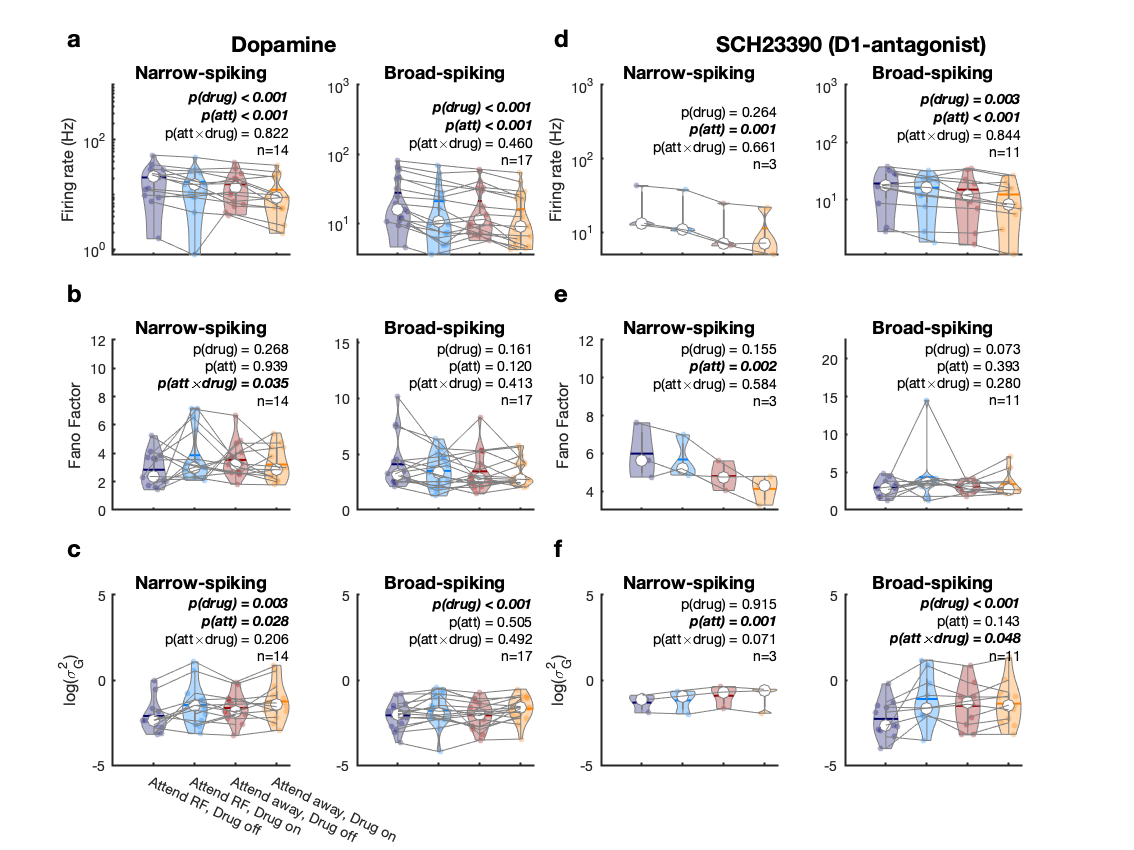


% create suptitle
ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized','clipping','off');
xpos_idx = 1:2:ncol;
for idrug = 1:num_drug
    xpos = (1/(ncol)) * xpos_idx(idrug);
    ht = text(xpos, 0.95, [label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title * 1.2, 'HorizontalAlignment', 'center');
    ht.FontWeight = 'bold';
end

## Post hoc comparisons: scatter plots and signed-rank tests, resolved for unit type

plotting and post-hoc tests

ncol = 2 * (length(label_drug));
nrow = 3; % 

markerstyle = {'o','v'};
colors_scatter = get_colors('spikewidth');

idx_subplot = [1 2 ncol+1 ncol+2 2*ncol+1 2*ncol+2; 3 4 ncol+3 ncol+4 2*ncol+3 2*ncol+4] ;
idx_axlabel = [1 NaN 2 NaN 3 NaN; 4 NaN 5 NaN 6 NaN];

[fH, fSet] = plotj_initFig('figNum', 2, 'width', 20, 'height', 16, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap .* [1 0.8];

[P, h_text] = deal( NaN(length(label_drug), nrow, 2, 2) ); % drugtype, actvity-type, attention, drug-offon,

for idrug = 1:length(label_drug)
    iplot=0;
    for irow = 1:nrow
        
        if irow == 1
            % mean rate
            datatype = 'rate';
            ylim2use = [0.7 120];
            
            scale ='Log';
            x_text = 0.005;
            y_text = [0.9 0.4];
        elseif irow == 2
            % Fano factor
            datatype = 'FF';
            ylim2use = [0 4];
            
            scale ='Linear';
            x_text = 0.1;
            y_text = [0.95 0.1];
        elseif irow == 3
            % Gain variability
            datatype = 'gain_log';
            ylim2use = [-4 2];
            
            scale ='Linear';
            x_text = 0.1;
            y_text = [0.95 0.1];
        end
        
        data2plot = att_table.(datatype);
        
        
        for iatt = 1:2
            iplot = iplot+1;
            
            subtightplot(nrow, ncol, idx_subplot(idrug, iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
            axH = plotj_initAx(fSet, 'axlabel', idx_axlabel(idrug, iplot), 'axlabelDisplacement', [0.05, 0.02]);
            hold on
            
            if irow==1 && iatt==1
                % sup-title
                set(gca,'units','normalized')
                text(100, 400, ['\bf ' label_drug{idrug}], 'FontSize', fSet.Fontsize_title, 'Interpreter', 'tex')
            end
            
            
            title(sprintf('Attend %s', label_attention{iatt}), 'FontSize', fSet.Fontsize_title)
            
            for iunitc = 1:2
                
                % unit selection
                idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
                idx_att = att_table.attention == label_attention{iatt};
                idx_unit_class = att_table.unit_class == label_unitclass{iunitc};
                
                unit2plot = idx_unit ...
                    & idx_att ...
                    & idx_unit_class;
                
                % extract data
                tmp_data = [data2plot(unit2plot & att_table.drug_on==label_drug_onoff{1}) ...
                    data2plot(unit2plot & att_table.drug_on==label_drug_onoff{2})];
                
                
                plotj_scatter(tmp_data, ...
                    'markerStyle', markerstyle(iunitc), 'MarkerSize', markersize, ...
                    'markerFaceColor', colors_scatter(iunitc,:), 'markerFaceAlpha', 0.5, ...
                    'markerEdgeColor', colors_scatter(iunitc,:), 'markerEdgeAlpha', 0.5, ...
                    'axislimit', ylim2use);
                
                % stats
                P(idrug,irow,iatt,iunitc) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
                
                % effect size
                d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
                
                % mean difference
                delta_data = tmp_data(:,2)-tmp_data(:,1);
                
                axis square
                p_string = get_significance_strings(P(idrug,irow,iatt,iunitc), 'rounded', 0);
                
                % print result
                fprintf('%s: %s, %s, attend %s: delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
                    datatype, ...
                    label_drug{idrug}, ...
                    label_unitclass{iunitc}, ...
                    label_attention{iatt}, ...
                    datatype, ...
                    mean(delta_data), ...
                    std(delta_data)/sqrt(length(tmp_data)), ...
                    p_string, ...
                    d)
                
                % plot text
                tmp_x = get(gca,'xlim');
                tmp_y = get(gca,'ylim');
                
                x_pos = get_value_range(tmp_x, x_text);
                y_pos = get_value_range(tmp_y, y_text(1)-y_text(2)*(iunitc-1));
                
                h_text(idrug,irow,iatt,iunitc) = text(x_pos, y_pos, ...
                    sprintf('%s', p_string), ...
                    'Color', colors_scatter(iunitc,:));
                
                if iatt==2
                    
                    x_pos = get_value_range(tmp_x, 0.6);
                    y_pos = get_value_range(tmp_y, 0.1+0.1*(iunitc-1));
                    
                    text(x_pos, y_pos, sprintf('%s (n=%d)', label_unitclass{iunitc}, length(tmp_data)), 'Color', colors_scatter(iunitc,:));
                end
            end
            
            
            xlim(ylim2use)
            ylim(ylim2use)
            set(gca,'YScale', scale, 'XScale', scale)
            % %     set(gca,'', [1 10 100])
            
            if strcmpi(datatype, 'rate')
                set(gca,'Xtick', [1 10 100], 'XTickLabel', [1 10 100])
                set(gca,'Ytick', [1 10 100], 'YTickLabel', [1 10 100])
                
                xlabel('Firing rate no drug (Hz)','FontSize', fSet.Fontsize_text)
                
                if idrug==1 && iatt==1
                    ylabel('Firing rate drug (Hz)','FontSize', fSet.Fontsize_text)
                end
            elseif strcmp(datatype, 'FF')
                xlabel('Fano Factor no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Fano Factor drug','FontSize', fSet.Fontsize_text)
                end
            elseif strcmp(datatype, 'gain_log')
                xlabel('Gain no drug','FontSize', fSet.Fontsize_text)
                if idrug==1 && iatt==1
                    ylabel('Gain drug','FontSize', fSet.Fontsize_text)
                end                
            end
        end
    end
end

rate: Dopamine, Narrow, attend Attend RF: delta-rate 3.60 +- 1.12, p = 0.009, Cohens's d = 0.86
rate: Dopamine, Broad, attend Attend RF: delta-rate 6.71 +- 1.22, p < 0.001, Cohens's d = 1.33
rate: Dopamine, Narrow, attend Attend away: delta-rate 3.22 +- 1.06, p = 0.009, Cohens's d = 0.81
rate: Dopamine, Broad, attend Attend away: delta-rate 4.92 +- 1.26, p < 0.001, Cohens's d = 0.95
FF: Dopamine, Narrow, attend Attend RF: delta-FF -1.03 +- 0.58, p = 0.119, Cohens's d = -0.47
FF: Dopamine, Broad, attend Attend RF: delta-FF 0.59 +- 0.39, p = 0.174, Cohens's d = 0.37
FF: Dopamine, Narrow, attend Attend away: delta-FF 0.33 +- 0.30, p = 0.326, Cohens's d = 0.30
FF: Dopamine, Broad, attend Attend away: delta-FF 0.16 +- 0.31, p = 0.927, Cohens's d = 0.12
gain_log: Dopamine, Narrow, attend Attend RF: delta-gain_log NaN +- NaN, p = 0.032, Cohens's d = -0.64
gain_log: Dopamine, Broad, attend Attend RF: delta-gain_log NaN +- NaN, p = 0.093, Cohens's d = -0.54
gain_log: Dopamine, Narrow, attend At

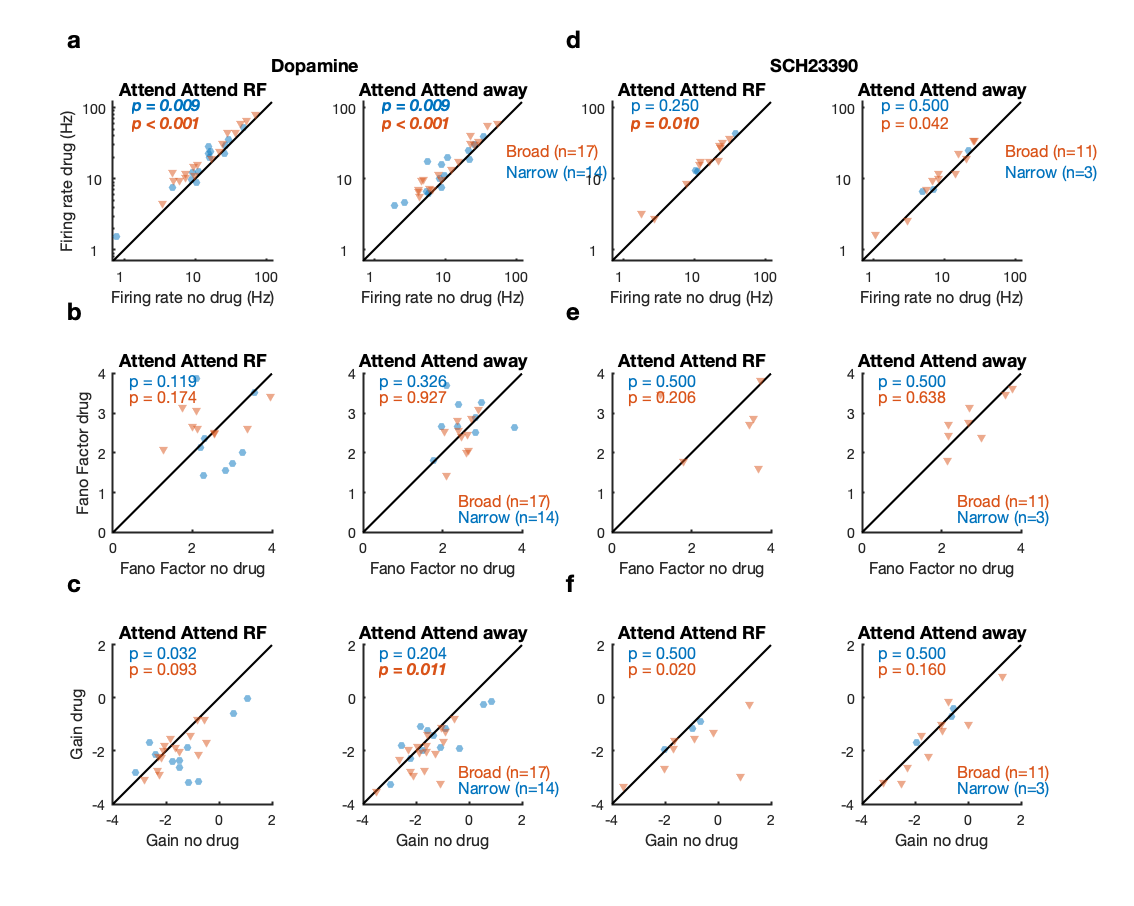


[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');

## plot gain, mean to variance relationship, separate for unit-types

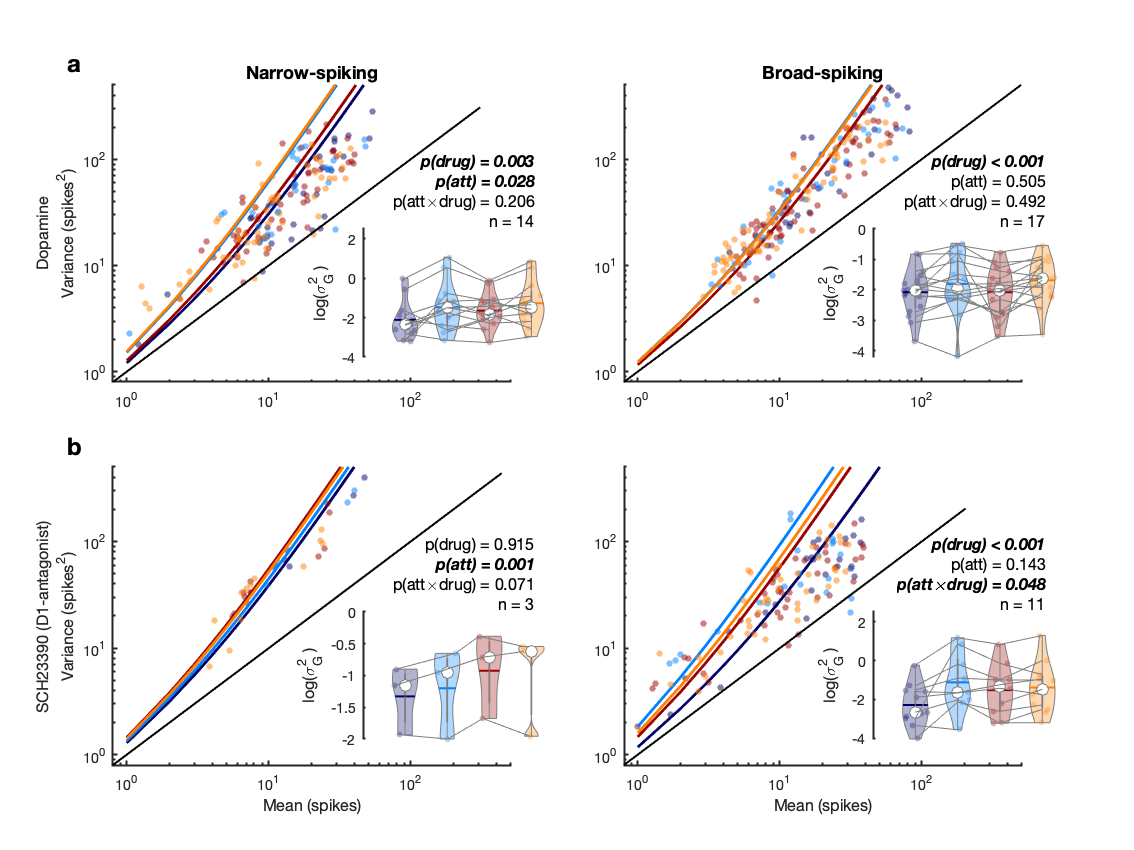

	 Found 14 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate    SE          tStat      DF    pValue        Lower        Upper    
    {'(Intercept)'                        }         -1.6769     0.24109    -6.9553    47    9.5535e-09      -2.1619      -1.1919
    {'drug_on_Drug on'                    }         0.23563    0.074521     3.1619    47      0.002744     0.085713      0.38555
    {'attention_Attend RF'                }        -0.16931    0.074521     -2.272    47      0.027706     -0.31923    -0.019394
    {'drug_on_Drug on:attention_Attend RF'}        0.097133    0.075694     1.2832    47       0.20571    -0.055145      0.24941



	 Found 17 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate     SE          tStat       DF    pValue        Lower       Upper   
    {'(Intercept)'                        }          -1.9154      0.1718     -11.149    63    1.5163e-16     -2.2587      -1.572
    {'drug_on_Drug on'                    }          0.16573    0.045026      3.6809    63    0.00048392    0.075757     0.25571
    {'attention_Attend RF'                }        -0.030159    0.045026    -0.66981    63       0.50543    -0.12014    0.059818
    {'drug_on_Drug on:attention_Attend RF'}        -0.031138    0.045026    -0.69156    63       0.49176    -0.12111    0.058839



	 Found 3 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate     SE          tStat      DF    pValue       Lower         Upper    
    {'(Intercept)'                        }          -1.1245     0.31895    -3.5257    8     0.0077812         -1.86     -0.38901
    {'drug_on_Drug on'                    }        0.0032421    0.029576    0.10962    8       0.91541     -0.064961     0.071446
    {'attention_Attend RF'                }          -0.1411    0.029576    -4.7706    8     0.0014075       -0.2093    -0.072895
    {'drug_on_Drug on:attention_Attend RF'}          0.06162    0.029576     2.0834    8      0.070737    -0.0065831      0.12982



	 Found 11 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate    SE          tStat      DF    pValue        Lower        Upper   
    {'(Intercept)'                        }        -1.6587      0.34668    -4.7845    37    2.7399e-05      -2.3611    -0.95625
    {'drug_on_Drug on'                    }        0.31791     0.088241     3.6027    37    0.00092093      0.13911      0.4967
    {'attention_Attend RF'                }        -0.1319     0.088241    -1.4948    37       0.14346     -0.31069    0.046895
    {'drug_on_Drug on:attention_Attend RF'}        0.17933     0.087884     2.0405    37      0.048482    0.0012596      0.3574



[colors, labels] = get_colors('att_drug');
[colors_violin, labels_violin, labels_violin_short] = get_colors('att_drug');
colors_violin = reshape(colors_violin, [4,3]);
labels_violin = reshape(labels_violin, [4,1]);

ncol = length(label_drug);
nrow = 2; % unit types

[fH, fSet] = plotj_initFig('width',20,'height',15,'Journal',plot_conventions);

clear legendText h
gain_table_full = [];

iplot=0;

xval_gain = 1:500;

for idrug = 1:length(label_drug)
    for iunitc = 1:length(unique(unitlist.unit_class))
        iplot = iplot+1;
        
        % unit selection
        idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
        idx_unit = idx_unit & att_table.unit_class==label_unitclass(iunitc);
        
        % subplot axis
        h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if iunitc==1
            plotj_initAx(fSet, 'axlabel', idrug);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if idrug==1
            h_title = title([label_unitclass{iunitc} '-spiking'], 'FontSize', fSet.Fontsize_title);
        end
        
        gv = unstack(att_table(idx_unit,:), 'gv', {'attention_drug_on'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        variable_names = gv.Properties.VariableNames;
        
        for iatt_drug = 1:length(labels_violin)
            
            mus = [gv.(labels_violin{iatt_drug}).mus];
            s2s = [gv.(labels_violin{iatt_drug}).s2s];
            
            mus = mus(:);
            s2s = s2s(:);
            
            % get binomial fit
            rhat = nanmean([gv.(labels_violin{iatt_drug}).rhat]);
            
            gv_pop = GainVariability;
            gv_pop.rhat = rhat;
            m2v = gv_pop.pred_variance(xval_gain);
            
            % plot
            h(iatt) = scatter(mus,s2s,fSet.MarkerSize*3,colors_violin(iatt_drug,:),'filled','MarkerFaceAlpha',0.5);
            plot(m2v.mean,m2v.variance,'Color',colors_violin(iatt_drug,:),'linew',fSet.LineWidth);
            xlim([0.8 max(xval_gain)])
            ylim([0.8 max(xval_gain)])
            plot([1e-10 max(s2s)*1.1],[1e-10 max(s2s)*1.1],'k','linew',1)
            set(gca,'xscale','log','yscale','log')
        end
        %         axis square
        %     legend(h(:),labels(:),'Location','SouthEast','Fontsize',fSet.Fontsize_text)
        
        if idrug==length(label_drug)
            xlabel('Mean (spikes)','FontSize',fSet.Fontsize_text)
        end
        if iunitc==1
            ylabel({[label_drug{idrug} label_drug_ext{idrug}],'Variance (spikes^{2})'},'FontSize',fSet.Fontsize_text)
        end
   
        % violin
        % init axes
        pos = get(h_ax, 'Position');
        h_ax_inset = axes('Position', [pos(1)+0.22 pos(2)+0.03 0.16 0.15]) ; % inset
        plotj_initAx(fSet);
        hold on
        
        % unit selection
        idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
        idx_unit = idx_unit & att_table.unit_class==label_unitclass(iunitc);
        
        num_unit_plot = length(unique(att_table.unit(idx_unit)));
        fprintf('\t Found %d units \n',  num_unit_plot)
        
        % extract smaller table
        v_att_table = att_table(idx_unit, ismember(att_table.Properties.VariableNames, {'gain_log','drug_on','attention','unit','attention_drug_on'}));
        
        % plot violin
        v = violinplot(v_att_table.gain_log, v_att_table.attention_drug_on, 'ShowMean', true);
        XTickLabel = get(gca,'XTickLabel');
        for iv = 1:length(v)
            v(iv).ScatterPlot.SizeData = 10;
            idx = strcmpi(XTickLabel(iv), labels_violin);
            v(iv).ViolinColor = colors_violin(idx,:);
        end
        set(gca,'XTickLabel',[])
        h_ax_inset.XAxis.Visible = 'off';
        
        % plot lines for each unit
        [data_x, data_y] = deal(NaN(num_unit_plot, length(length(v))));
        for iv = 1:length(v)
            if ~any(isnan(v_att_table.gain_log))
                % works if data is complete
                data_x(:,iv) = v(iv).ScatterPlot.XData;
                data_y(:,iv) = v(iv).ScatterPlot.YData;
            else
                % catch if nan values are present
                idx = strcmpi(XTickLabel(iv), labels_violin);
                
                idx_trial = v_att_table.attention_drug_on==labels_violin{idx};
                data_x(:,iv) = iv;
                data_y(:,iv) = v_att_table.gain_log(idx_trial);
            end
        end
        plot(data_x', data_y', 'Color', [0.5 0.5 0.5 0.3]);
        
        % fit model
        lme_population = fitlme(v_att_table,['gain_log ~ 1 + attention*drug_on + (1|unit)'],'DummyVarCoding','effects'); % fit interaction model with effect coding
        disp(lme_population.Coefficients)
        
        coefficients = lme_population.Coefficients;
        
        betas = coefficients.Estimate(2:end);
        betas_se = coefficients.SE(2:end);
        p_val = coefficients.pValue(2:end);
        
        %         p_string = get_significance_strings(p_val, 'rounded', 0);
        p_string = get_significance_strings(p_val, 'rounded', 0, 'factorstring', {'drug','att',sprintf('att%sdrug', '\times')});
        p_string{end+1} = ['n = ' num2str(num_unit_plot)];
        
        % plot text
        YLIM = get(gca,'ylim');
        set(gca, 'ylim', YLIM .* [1 1.25])
        
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.95);
        y_pos = get_value_range(tmp_y, 1.3);
        
        h_text = text(x_pos, y_pos, p_string,'HorizontalAlignment','right');
        
        ylabel('log(\sigma^{2}_G )', 'FontSize', fSet.Fontsize_text)
        
        %         [p_fdr, p_masked] = FDR(p_val, 0.05);
        [p_masked] = p_val<0.05;
        p_masked = [p_masked ; false];
        plotj_text_emphasise(h_text, 1, 'italic', p_masked);
        plotj_text_emphasise(h_text, 1, 'bold', p_masked);
    end
end

## Attend ROC, drug/no drug, narrow/broad. DrugMI-ejecCurrent

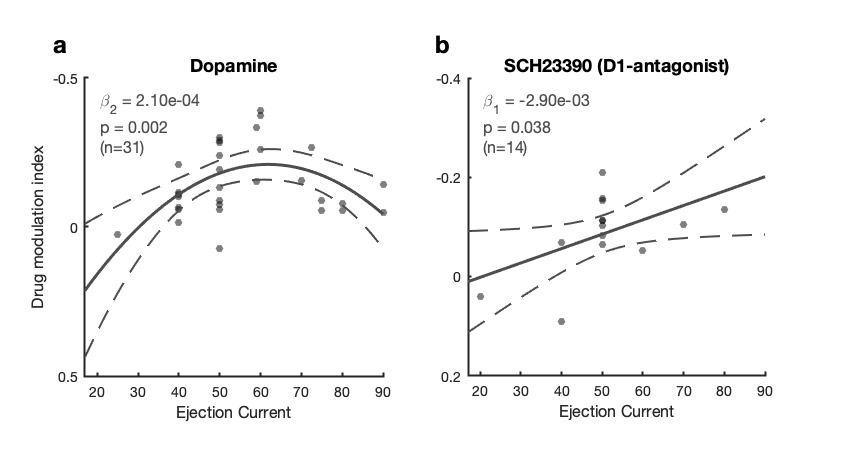

% datatype for dose-response curve
datatype = 'MI';
% datatype = 'AUROC';
% datatype = 'gain_log';

markerstyle = {'o','o'};


ncol = length(label_drug) ;
nrow = 1;

[fH, fSet] = plotj_initFig('width', 15, 'height', 8, 'Journal',plot_conventions);

switch datatype
    case 'MI'
        v_drug_table = unstack(drug_table, 'MI', {'attention'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        data2plot = mean([v_drug_table.("Attend RF") v_drug_table.("Attend away")],2);
        
        iunitc=[];
        
        ylabel2use = 'Drug modulation index';
        ylim2use = {[-0.5 0.5],[-0.4 0.2]};
    case 'AUROC'
        
        % get data - AUROC
        idx_cond = att_table.attention=='Attend RF';
        
        tmp_data = zeros(length(find(idx_cond))/2,1);
        tmp_data(:,1) = att_table.roc(idx_cond & att_table.drug_on=='Drug off');
        tmp_data(:,2) = att_table.roc(idx_cond & att_table.drug_on=='Drug on');
        
        data2plot = diff(tmp_data,1,2);
        
        iunitc = [];
        
        ylabel2use = [plotj_symbol('Delta') ' attention AUROC'];
        ylim2use = {[-0.25 0.3],[-0.25 0.3]};
    case 'gain_log'
        
        
        v_att_table = unstack(att_table, 'gain_log', {'attention_drug_on'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        
        % difference in attentional modulation of gain variabiliy
        data2plot1 = (v_att_table.("Attend RF, Drug on") - v_att_table.("Attend away, Drug on")) ./ (v_att_table.("Attend RF, Drug on") + v_att_table.("Attend away, Drug on"));
        data2plot2 = (v_att_table.("Attend RF, Drug off") - v_att_table.("Attend away, Drug off")) ./ (v_att_table.("Attend RF, Drug off") + v_att_table.("Attend away, Drug off"));
        data2plot = data2plot1 - data2plot2;
        iunitc=[];
        
end

clear ax h
for idrug = 1:length(label_drug)
    clear text_legend
    
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    
    ax(idrug) = subtightplot(nrow, ncol, idrug, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', idrug);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
    
    % ejectionCurrent
    xlabel_event = 'Ejection Current';
    xlim2use = [17 90];
    
    tmp_data = [unitlist.EjectCurrent(idx_unit)  data2plot(idx_unit)];
    hscat = plotj_scatter(tmp_data, ...
        'markerStyle', markerstyle, 'markerSize', markersize, ...
        'markerFaceColor', 'k', 'markerFaceAlpha', 0.5, ...
        'axislimit', [], ...
        'unityLine', 0);
    text_legend{1} = ['(n=' num2str(length(find(idx_unit))) ')'];
    
    
    data_table = table(unitlist.EjectCurrent_centered(idx_unit), data2plot(idx_unit), 'VariableNames', {'x', 'y'});
    [stats2report, predict_data, stats, model] = fitlme_singleVar_sequential(data_table, 0);
    
    predict_data.x = predict_data.x + mean(unique(unitlist.EjectCurrent));
    
    switch datatype
        case 'MI'
            filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
        case 'AUROC'
            filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
        case 'gain_log'
    end
    writetable(data_table, filename)
    
    %     fprintf('Chi(%d) %1.2f, p = %1.3f\n', stats2report.deltaDF, stats2report.LRStat, stats2report.pValue)
    
    if any(strcmp('fit_mean', predict_data.Properties.VariableNames))
        h = plot(predict_data.x, predict_data.fit_mean, 'linewidth', fSet.LineWidth, 'color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_low, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_high, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        [pstring_chi,starstring] = get_significance_strings(stats2report.pValue, 'rounded', 0);
        
        cond1 = exist([filename(1:end-4) '_R.csv'], 'file');
        cond2 = strcmpi(model,'quadratic');
        if cond1 && cond2
            utable = readtable([filename(1:end-4) '_R.csv']);
            
            if utable.usig==1
                pstring_chi = [pstring_chi ' (U^{+})'];
            else
                pstring_chi = [pstring_chi ' (U^{-})'];
            end
        end
        
    else
        pstring_chi = '';
    end
    
    
    switch model
        case 'linear'
            betaString = ['\beta' '_{1} = ' num2str(stats.Estimate, '%1.2e')];
            %         model_color = colors(2,:);
        case 'quadratic'
            betaString = ['\beta' '_{2} = ' num2str(stats.Estimate, '%1.2e')];
        otherwise
            betaString = [];
    end
    
    axis square
    xlabel(xlabel_event, 'FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel(ylabel2use, 'FontSize', fSet.Fontsize_text)
    end
    
    if ~isempty(ylim2use)
        ylim(ylim2use{idrug})
    end
    if ~isempty(xlim2use)
        xlim(xlim2use)
    end
    
    % set ax param
    set(gca,'YDir','reverse')
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.05);
    y_pos = get_value_range(tmp_y, 0.15);
    
    text(x_pos, y_pos, {betaString, pstring_chi, text_legend{1}}, 'fontsize', fSet.Fontsize_text, 'color', [0.3 0.3 0.3])
    
end

## Attend ROC, drug/no drug, resolved for narrow/broad. DrugMI-ejecCurrent

% datatype for dose-response curve
datatype = 'MI';
% datatype = 'AUROC';
% datatype = 'gain_log';

colors = get_colors('spikewidth');
markerstyle = {'o','o'};


idx_group = 1;

ncol = length(label_drug);
nrow = 2;

[fH, fSet] = plotj_initFig('width', 20, 'height', 14, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap.*[1.2 .8];

axislim = [0.25 0.9];
[P, h_text] = deal( NaN(length(label_drug), 2) ); % drugtype, unit-type,
[P_roc, h_text_roc] = deal( NaN(length(label_drug), 2) ); % drugtype, unit-type,
iplot=0;
for idrug = 1:length(label_drug)
    iplot = iplot+1;
    
    % unit selection
    idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
    
    % subplot axis
    h_ax_subplot = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
    
    % inset axis
    pos = get(h_ax_subplot, 'Position');
    h_ax_inset = axes('Position', [pos(1)+0.28 pos(2)+0.035 0.1 0.11]) ; % inset
    plotj_initAx(fSet);
    hold on
    
    % lme
    for iunitc = 1:2
        
        set(fH, 'currentaxes', h_ax_subplot);
        
        unit2plot = idx_unit & att_table.unit_class==label_unitclass(iunitc);
        
        % get data - AUROC
        idx_cond = att_table.attention=='Attend RF';
        
        idx = unit2plot & idx_cond;
        tmp_data = zeros(length(find(idx))/2,1);
        tmp_data(:,1) = att_table.roc(idx & att_table.drug_on=='Drug off');
        tmp_data(:,2) = att_table.roc(idx & att_table.drug_on=='Drug on');
        
        %         [bf10,p,CI,stats] = bf.ttest(tmp_data(:,1),tmp_data(:,2))
        plotj_scatter(tmp_data, ...
            'markerStyle', markerstyle, 'MarkerSize', markersize, ...
            'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
            'markerEdgeColor', colors(iunitc,:), 'markerEdgeAlpha', 0.5, ...
            'axislimit', axislim);
        % stats
        P(idrug,iunitc) = compare_means(tmp_data(:,1),tmp_data(:,2), 1, 'rank');
        
        axis square
        p_string = get_significance_strings(P(idrug,iunitc), 'rounded', 0);
        
        % mean difference
        delta_data = tmp_data(:,2)-tmp_data(:,1);
        
        % effect size
        d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
        
        % print result
        fprintf('%s: %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'AUROC', ...
            label_drug{idrug}, ...
            'AUROC', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(size(tmp_data,1)), ...
            p_string, ...
            d)
        
        % set text
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.05);
        y_pos = get_value_range(tmp_y, 0.95 - 0.07 * (iunitc-1));
        
        h_text(idrug,iunitc) = text(x_pos, y_pos, ...
            sprintf('%s (n=%d)', p_string, size(tmp_data,1)), ...
            'Color', colors(iunitc,:), 'FontSize', fSet.Fontsize_ax);
        
        % inset
        % -----
        idx = tmp_data(:,1)<0.5;
        tmp_data(idx,:) = 1-tmp_data(idx,:);
        %         [bf10,p,CI,stats] = bf.ttest(tmp_data(:,1),tmp_data(:,2))
        P_roc(idrug,iunitc) = compare_means(tmp_data(:,1),tmp_data(:,2), 1, 'rank');
        
        bar_data = diff(tmp_data,1,2);
        
        bar_y = mean(bar_data);
        bar_y_err = std(bar_data)/sqrt(length(bar_data));
        
        % plot
        set(fH, 'currentaxes', h_ax_inset);
        h_scatter = scatter(iunitc + (rand(length(bar_data),1)-0.5)*0.1, bar_data, ...
            '.', 'MarkerFaceColor', colors(iunitc,:),'MarkerEdgeColor', colors(iunitc,:));
        h_scatter.MarkerFaceAlpha = 0.5;
        h_scatter.MarkerEdgeAlpha = 0.5;
        
        plot(iunitc + [-0.25 0.25], [bar_y bar_y], 'Color', colors(iunitc,:), 'linew', fSet.LineWidth+1)
        plot(iunitc + [0 0], bar_y + [-bar_y_err bar_y_err], 'Color', colors(iunitc,:), 'linew', fSet.LineWidth)
        
        p_string = get_significance_strings(P_roc(idrug,iunitc), 'rounded', 0);
        
        % mean difference
        delta_data = tmp_data(:,2)-tmp_data(:,1);
        
        % effect size
        d = computeCohen_d(tmp_data(:,2), tmp_data(:,1), 'paired');
        
        % print result
        fprintf('%s: %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'AUROC-CORRECT', ...
            label_drug{idrug}, ...
            'AUROC', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(size(tmp_data,1)), ...
            p_string, ...
            d)
        
        % set text
        % tmp_y = get(gca,'ylim');
        %y_pos = get_value_range(tmp_y, 0.95);
        y_pos = 0.1*idrug;
        
        h_text_roc(idrug,iunitc) = text(iunitc+0.1, y_pos, ...
            p_string, ...
            'Color', colors(iunitc,:), ...
            'FontSize', fSet.Fontsize_ax);
    end
    
    set(h_ax_inset, 'XTick', [1 2])
    %     ylabel(h_ax_inset, [plotj_symbol('Delta') ' | AUROC-0.5 |'],'FontSize', fSet.Fontsize_text)
    ylabel(h_ax_inset, [plotj_symbol('Delta') ' AUROC-c'],'FontSize', fSet.Fontsize_text)
    
    xlabel(h_ax_subplot, 'Attention AUROC no drug','FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel(h_ax_subplot, 'Attention AUROC drug','FontSize', fSet.Fontsize_text)
    end
end

AUROC: Dopamine, delta-AUROC 0.00 +- 0.02, p = 0.952, Cohens's d = 0.03


AUROC-CORRECT: Dopamine, delta-AUROC -0.01 +- 0.02, p = 0.542, Cohens's d = -0.16


AUROC: Dopamine, delta-AUROC -0.03 +- 0.01, p = 0.009, Cohens's d = -0.69


AUROC-CORRECT: Dopamine, delta-AUROC -0.02 +- 0.01, p = 0.080, Cohens's d = -0.38


AUROC: SCH23390, delta-AUROC -0.03 +- 0.04, p = 0.750, Cohens's d = -0.54


AUROC-CORRECT: SCH23390, delta-AUROC -0.03 +- 0.04, p = 0.750, Cohens's d = -0.54


AUROC: SCH23390, delta-AUROC -0.02 +- 0.04, p = 0.700, Cohens's d = -0.15


AUROC-CORRECT: SCH23390, delta-AUROC -0.04 +- 0.03, p = 0.278, Cohens's d = -0.33


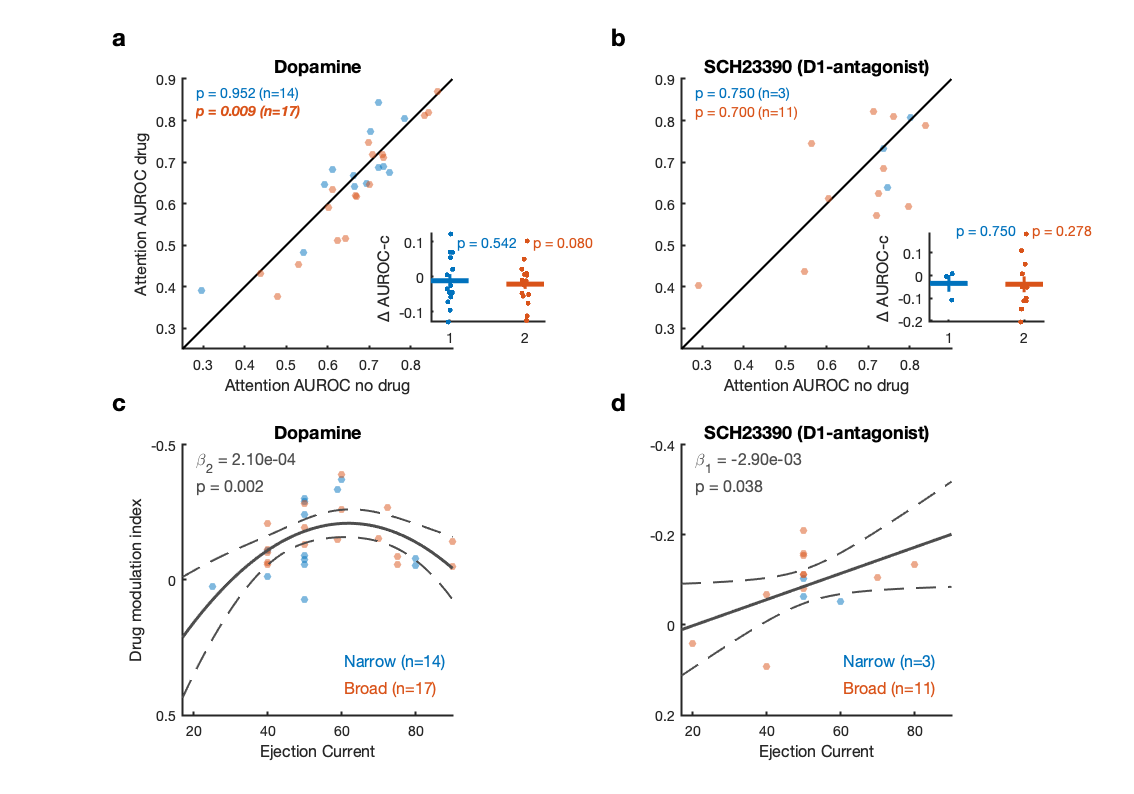

ans = 31

ans = 14


% FDR correction
[p_fdr, p_masked] = FDR(P, 0.05);
[p_fdr, p_masked_corr] = FDR(P_roc, 0.05);

plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');


% drugMI/attAUROC against ejection current

switch datatype
    case 'MI'
        v_drug_table = unstack(drug_table, 'MI', {'attention'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        data2plot = mean([v_drug_table.("Attend RF") v_drug_table.("Attend away")],2);
        
        iunitc=[];
        
        ylabel2use = 'Drug modulation index';
        ylim2use = {[-0.5 0.5],[-0.4 0.2]};
    case 'AUROC'
        
        % get data - AUROC
        idx_cond = att_table.attention=='Attend RF';
        
        tmp_data = zeros(length(find(idx_cond))/2,1);
        tmp_data(:,1) = att_table.roc(idx_cond & att_table.drug_on=='Drug off');
        tmp_data(:,2) = att_table.roc(idx_cond & att_table.drug_on=='Drug on');
        
        data2plot = diff(tmp_data,1,2);
        
        iunitc = [];
        
        ylabel2use = [plotj_symbol('Delta') ' attention AUROC'];
        ylim2use = {[-0.25 0.3],[-0.25 0.3]};
    case 'gain_log'
        
        
        v_att_table = unstack(att_table, 'gain_log', {'attention_drug_on'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        
        % difference in attentional modulation of gain variabiliy
        data2plot1 = (v_att_table.("Attend RF, Drug on") - v_att_table.("Attend away, Drug on")) ./ (v_att_table.("Attend RF, Drug on") + v_att_table.("Attend away, Drug on"));
        data2plot2 = (v_att_table.("Attend RF, Drug off") - v_att_table.("Attend away, Drug off")) ./ (v_att_table.("Attend RF, Drug off") + v_att_table.("Attend away, Drug off"));
        data2plot = data2plot1 - data2plot2;
        iunitc=[];
        
end

clear ax h
for idrug = 1:ncol
    clear text_legend
    iplot=iplot+1;
    
    idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
    
    ax(idrug) = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
    plotj_initAx(fSet, 'axlabel', iplot, 'axlabelDisplacement', [0.01, 0.02]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
    
    if ~isempty(iunitc)
        unit2plot = idx_unit & unitlist.unit_class==label_unitclass(iunitc);
    else
        unit2plot = idx_unit;
    end
    length(find(unit2plot))
    
    % ejectionCurrent
    xlabel_event = 'Ejection Current';
    xlim2use = [17 90];
    
    if length(unique(unitlist.unit_class(unit2plot)))==1
        tmp_data = [unitlist.EjectCurrent(unit2plot)  data2plot(unit2plot)];
        hscat = plotj_scatter(tmp_data, ...
            'markerStyle', markerstyle, 'markerSize', markersize, ...
            'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
            'axislimit', [], ...
            'unityLine', 0);
        text_legend{1} = [label_unitclass{iunitc} ' (n=' num2str(length(find(unitlist.unit_class(idx_unit)==iunitc))) ')'];
    else
        tmp_data = [unitlist.EjectCurrent(unit2plot)  data2plot(unit2plot)];
        hscat = plotj_scatter(tmp_data, ...
            'dataIndex', grp2idx(unitlist.unit_class(unit2plot)), ...
            'markerStyle', markerstyle, 'MarkerSize', markersize, ...
            'markerFaceColor', (colors(1:2,:)), 'markerFaceAlpha', [0.5 0.5], ...
            'markerEdgeColor', (colors(1:2,:)), 'markerEdgeAlpha', [0.5 0.5], ...
            'axislimit', [], ...
            'unityLine', 0);
        text_legend{1} = [label_unitclass{1} ' (n=' num2str(length(find(unitlist.unit_class(idx_unit)==label_unitclass(1)))) ')'];
        text_legend{2} = [label_unitclass{2} ' (n=' num2str(length(find(unitlist.unit_class(idx_unit)==label_unitclass(2)))) ')'];
    end
    
    data_table = table(unitlist.EjectCurrent_centered(unit2plot), data2plot(unit2plot), 'VariableNames', {'x', 'y'});
    [stats2report, predict_data, stats, model] = fitlme_singleVar_sequential(data_table, 0);
    
    predict_data.x = predict_data.x + mean(unique(unitlist.EjectCurrent));
    
    switch datatype
        case 'MI'
            filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
        case 'AUROC'
            filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s_%s.csv', label_drug{idrug}, selectivity_criterium));
        case 'gain_log'
    end
    writetable(data_table, filename)
    
    %     fprintf('Chi(%d) %1.2f, p = %1.3f\n', stats2report.deltaDF, stats2report.LRStat, stats2report.pValue)
    
    if any(strcmp('fit_mean', predict_data.Properties.VariableNames))
        h = plot(predict_data.x, predict_data.fit_mean, 'linewidth', fSet.LineWidth, 'color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_low, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        h = plot(predict_data.x, predict_data.fit_CI_high, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
        [pstring_chi,starstring] = get_significance_strings(stats2report.pValue, 'rounded', 0);
        
        cond1 = exist([filename(1:end-4) '_R.csv'], 'file');
        cond2 = strcmpi(model,'quadratic');
        if cond1 && cond2
            utable = readtable([filename(1:end-4) '_R.csv']);
            
            if utable.usig==1
                pstring_chi = [pstring_chi ' (U^{+})'];
            else
                pstring_chi = [pstring_chi ' (U^{-})'];
            end
        end
        
    else
        pstring_chi = '';
    end
    
    
    switch model
        case 'linear'
            betaString = ['\beta' '_{1} = ' num2str(stats.Estimate, '%1.2e')];
            %         model_color = colors(2,:);
        case 'quadratic'
            betaString = ['\beta' '_{2} = ' num2str(stats.Estimate, '%1.2e')];
        otherwise
            betaString = [];
    end
    
    axis square
    xlabel(xlabel_event, 'FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel(ylabel2use, 'FontSize', fSet.Fontsize_text)
    end
    
    if ~isempty(ylim2use)
        ylim(ylim2use{idrug})
    end
    if ~isempty(xlim2use)
        xlim(xlim2use)
    end
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.6);
    y_pos(1) = get_value_range(tmp_y, 0.8);
    y_pos(2) = get_value_range(tmp_y, 0.9);
    
    text(x_pos, y_pos(1), text_legend{1}, 'FontSize', fSet.Fontsize_text, 'Color', colors(1,:))
    text(x_pos, y_pos(2), text_legend{2}, 'FontSize', fSet.Fontsize_text, 'Color', colors(2,:))
    
    % set ax param
    set(gca,'YDir','reverse')
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.05);
    y_pos = get_value_range(tmp_y, 0.1);
    
    text(x_pos, y_pos, {betaString, pstring_chi }, 'fontsize', fSet.Fontsize_text, 'color', [0.3 0.3 0.3])
    
end

## DrugMI-ejecCurrent across selectivity indices

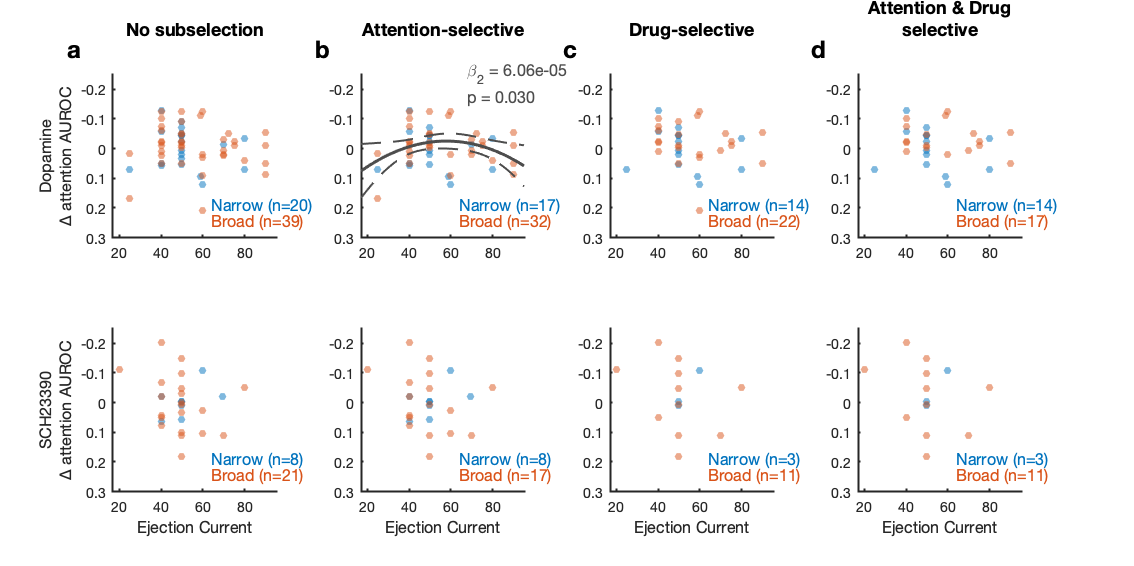

Chi(1) 0.42, p = 0.515
Chi(1) 0.82, p = 0.365
Chi(1) 4.71, p = 0.030
Chi(1) 0.74, p = 0.390
Chi(1) 1.03, p = 0.311
Chi(1) 0.80, p = 0.370
Chi(1) 0.69, p = 0.406
Chi(1) 0.80, p = 0.370


colors = get_colors('spikewidth');

datatype = 'MI';
datatype = 'AUROC';


selectivity_criteria = {'none', 'att', 'dru', 'att&dru'};
label_criteria = {'No subselection', 'Attention-selective', 'Drug-selective', {'Attention & Drug', 'selective'}};

ncol = length(selectivity_criteria);
nrow = length(label_drug);
iplot = 0;

[fH, fSet] = plotj_initFig('width', 20, 'height', 10, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap.*[1 .75];

idx_subplot = [1:ncol ; (ncol+1):ncol*2];

% drugMI/attAUROC against ejection current

switch datatype
    case 'MI'
        v_drug_table = unstack(drug_table, 'MI', {'attention'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        data2plot = mean([v_drug_table.("Attend RF") v_drug_table.("Attend away")],2);
        
        iunitc=[];
        
        ylabel2use = 'Drug modulation index';
        ylim2use = [];
    case 'AUROC'
        %         data2plot = squeeze(diff(rate_ROC.roc,1,2));
        %         data2plot = squeeze(mean(data2plot(:,idx_attention_roc==1),2)); % average over relevant auroc conditions
        
        idx_cond = att_table.attention=='Attend RF';
        
        tmp_data = zeros(length(find(idx_cond))/2,1);
        tmp_data(:,1) = att_table.roc(idx_cond & att_table.drug_on=='Drug off');
        tmp_data(:,2) = att_table.roc(idx_cond & att_table.drug_on=='Drug on');
        
        data2plot = diff(tmp_data,1,2);
        
        
        iunitc = [];
        
        ylabel2use = [plotj_symbol('Delta') ' attention AUROC'];
        ylim2use = [-0.25 0.3];
end

[P,h_text] = deal(zeros(length(selectivity_criteria), length(label_drug)));
for icrit = 1:length(selectivity_criteria)
    
    selectivity_criterium = selectivity_criteria{icrit};
    
    clear ax h
    for idrug = 1:length(label_drug)
        clear text_legend
        iplot=iplot+1;
        
        idx_unit = get_unit_selectivity(unitlist, selectivity_criterium, {'drug',label_drug(idrug)});
        
        ax(idrug) = subtightplot(nrow, ncol, idx_subplot(iplot), fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if idrug==1
            plotj_initAx(fSet, 'axlabel', icrit);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if idrug==1
            % title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
            h_title = title(label_criteria{icrit}, 'FontSize', fSet.Fontsize_title);
            set(h_title, 'Units', 'normalized');
            h_title.Position = h_title.Position+[0 0.2 0];
        end
        if ~isempty(iunitc)
            unit2plot = idx_unit & unitlist.unit_class==label_unitclass{iunitc};
        else
            unit2plot = idx_unit;
        end
        
        % ejectionCurrent
        xlabel_event = 'Ejection Current';
        xlim2use = [17 95];
        
        if length(unique(unitlist.unit_class(unit2plot)))==1
            tmp_data = [unitlist.EjectCurrent(unit2plot)  data2plot(unit2plot)];
            hscat = plotj_scatter(tmp_data, ...
                'markerStyle', {'.'}, 'markerSize', markersize, ...
                'markerFaceColor', colors(iunitc,:), 'markerFaceAlpha', 0.5, ...
                'axislimit', [], ...
                'unityLine', 0);
            text_legend{1} = [label_unitclass{iunitc} ' (n=' num2str(length(find(unit_class(idx_unit)==iunitc))) ')'];
        else
            tmp_data = [unitlist.EjectCurrent(unit2plot)  data2plot(unit2plot)];
            hscat = plotj_scatter(tmp_data, ...
                'dataIndex', grp2idx(unitlist.unit_class(unit2plot)), ...
                'markerStyle', {'o','o'}, 'MarkerSize', markersize, ...
                'markerFaceColor', (colors(1:2,:)), 'markerFaceAlpha', [0.5 0.5], ...
                'markerEdgeColor', (colors(1:2,:)), 'markerEdgeAlpha', [0.5 0.5], ...
                'axislimit', [], ...
                'unityLine', 0);
            text_legend{1} = [label_unitclass{1} ' (n=' num2str(length(find(unitlist.unit_class(idx_unit)==label_unitclass(1)))) ')'];
            text_legend{2} = [label_unitclass{2} ' (n=' num2str(length(find(unitlist.unit_class(idx_unit)==label_unitclass(2)))) ')'];
        end
        
        data_table = table(unitlist.EjectCurrent(unit2plot), data2plot(unit2plot), 'VariableNames', {'x', 'y'});
        [stats2report, predict_data, stats, model] = fitlme_singleVar_sequential(data_table, 0);
        P(icrit,idrug) = stats2report.pValue;
        
        switch datatype
            case 'MI'
                filename = fullfile(path_population, sprintf('doseResponse_drugMI_%s_%s.csv', label_drug{idrug}, selectivity_criteria{icrit}));
            case 'AUROC'
                filename = fullfile(path_population, sprintf('doseResponse_attAUROC_%s_%s.csv', label_drug{idrug}, selectivity_criteria{icrit}));
        end
        writetable(data_table, filename);
        
        fprintf('Chi(%d) %1.2f, p = %1.3f\n', stats2report.deltaDF, stats2report.LRStat, stats2report.pValue)
        
        if any(strcmp('fit_mean', predict_data.Properties.VariableNames))
            h = plot(predict_data.x, predict_data.fit_mean, 'linewidth', fSet.LineWidth, 'color', [0.3 0.3 0.3]);
            h = plot(predict_data.x, predict_data.fit_CI_low, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
            h = plot(predict_data.x, predict_data.fit_CI_high, '--', 'linewidth', fSet.LineWidth_in, 'Color', [0.3 0.3 0.3]);
            [pstring_chi,starstring] = get_significance_strings(stats2report.pValue, 'rounded', 0);
            
            cond1 = exist([filename(1:end-4) '_R.csv'], 'file');
            cond2 = strcmpi(model,'quadratic');
            if cond1 && cond2
                utable = readtable([filename(1:end-4) '_R.csv']);
                
                if utable.usig==1
                    pstring_chi = [pstring_chi ' (U^{+})'];
                else
                    pstring_chi = [pstring_chi ' (U^{-})'];
                end
            end
            
        else
            pstring_chi = '';
        end
        
        switch model
            case 'linear'
                betaString = ['\beta' '_{1} = ' num2str(stats.Estimate, '%1.2e')];
                %         model_color = colors(2,:);
            case 'quadratic'
                betaString = ['\beta' '_{2} = ' num2str(stats.Estimate, '%1.2e')];
            otherwise
                betaString = [];
        end
        
        axis square
        if idrug==length(label_drug)
            xlabel(xlabel_event, 'FontSize', fSet.Fontsize_text)
        end
        if icrit==1
            ylabel({label_drug{idrug},ylabel2use}, 'FontSize', fSet.Fontsize_text)
        end
        
        if ~isempty(ylim2use)
            ylim(ylim2use)
        end
        if ~isempty(xlim2use)
            xlim(xlim2use)
        end
        
        % plot text indicating number of units
        set(gca, 'Units', 'normalized');
        
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.6);
        y_pos(1) = get_value_range(tmp_y, 0.8);
        y_pos(2) = get_value_range(tmp_y, 0.9);
        
        text(x_pos, y_pos(1), text_legend{1}, 'FontSize', fSet.Fontsize_text, 'Color', colors(1,:))
        text(x_pos, y_pos(2), text_legend{2}, 'FontSize', fSet.Fontsize_text, 'Color', colors(2,:))
        
        % set ax param
        set(gca,'YDir','reverse')
        
        % plot text with stats
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        switch label_drug{idrug}
            case 'Dopamine'
                x_pos = get_value_range(tmp_x, 0.65);
                y_pos = get_value_range(tmp_y, 0.05);
            case 'SCH23390'
                x_pos = get_value_range(tmp_x, 0.05);
                y_pos = get_value_range(tmp_y, 0);
        end
        
        h_text(icrit,idrug) = text(x_pos, y_pos, {betaString, pstring_chi}, 'fontsize', fSet.Fontsize_text, 'color', [0.3 0.3 0.3]);
        
    end
end


% multiple comparison correction, individual models
[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic', 2);
plotj_text_emphasise(h_text, p_masked, 'bold', 2);



## plot gain, mean to variance relationship, separate for unit-types

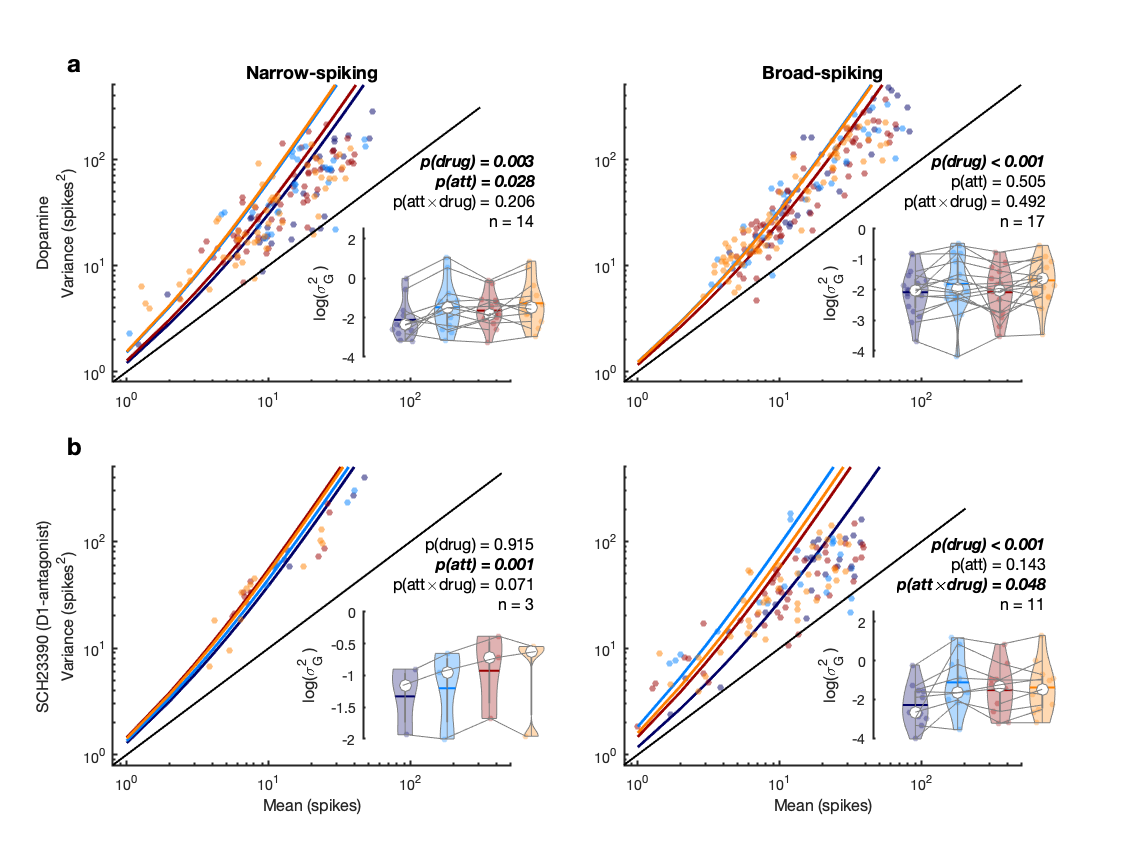

	 Found 14 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate    SE          tStat      DF    pValue        Lower        Upper    
    {'(Intercept)'                        }         -1.6769     0.24109    -6.9553    47    9.5535e-09      -2.1619      -1.1919
    {'drug_on_Drug on'                    }         0.23563    0.074521     3.1619    47      0.002744     0.085713      0.38555
    {'attention_Attend RF'                }        -0.16931    0.074521     -2.272    47      0.027706     -0.31923    -0.019394
    {'drug_on_Drug on:attention_Attend RF'}        0.097133    0.075694     1.2832    47       0.20571    -0.055145      0.24941



	 Found 17 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate     SE          tStat       DF    pValue        Lower       Upper   
    {'(Intercept)'                        }          -1.9154      0.1718     -11.149    63    1.5163e-16     -2.2587      -1.572
    {'drug_on_Drug on'                    }          0.16573    0.045026      3.6809    63    0.00048392    0.075757     0.25571
    {'attention_Attend RF'                }        -0.030159    0.045026    -0.66981    63       0.50543    -0.12014    0.059818
    {'drug_on_Drug on:attention_Attend RF'}        -0.031138    0.045026    -0.69156    63       0.49176    -0.12111    0.058839



	 Found 3 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate     SE          tStat      DF    pValue       Lower         Upper    
    {'(Intercept)'                        }          -1.1245     0.31895    -3.5257    8     0.0077812         -1.86     -0.38901
    {'drug_on_Drug on'                    }        0.0032421    0.029576    0.10962    8       0.91541     -0.064961     0.071446
    {'attention_Attend RF'                }          -0.1411    0.029576    -4.7706    8     0.0014075       -0.2093    -0.072895
    {'drug_on_Drug on:attention_Attend RF'}          0.06162    0.029576     2.0834    8      0.070737    -0.0065831      0.12982



	 Found 11 units 



    Fixed effect coefficients: DFMethod = 'Residual', Alpha = 0.05

    Name                                           Estimate    SE          tStat      DF    pValue        Lower        Upper   
    {'(Intercept)'                        }        -1.6587      0.34668    -4.7845    37    2.7399e-05      -2.3611    -0.95625
    {'drug_on_Drug on'                    }        0.31791     0.088241     3.6027    37    0.00092093      0.13911      0.4967
    {'attention_Attend RF'                }        -0.1319     0.088241    -1.4948    37       0.14346     -0.31069    0.046895
    {'drug_on_Drug on:attention_Attend RF'}        0.17933     0.087884     2.0405    37      0.048482    0.0012596      0.3574



[colors, labels] = get_colors('att_drug');
[colors_violin, labels_violin, labels_violin_short] = get_colors('att_drug');
colors_violin = reshape(colors_violin, [4,3]);
labels_violin = reshape(labels_violin, [4,1]);

ncol = length(label_drug);
nrow = 2; % unit types

[fH, fSet] = plotj_initFig('width',20,'height',15,'Journal',plot_conventions);

clear legendText h
gain_table_full = [];

iplot=0;

xval_gain = 1:500;

for idrug = 1:length(label_drug)
    for iunitc = 1:length(unique(unitlist.unit_class))
        iplot = iplot+1;
        
        % unit selection
        idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
        idx_unit = idx_unit & att_table.unit_class==label_unitclass(iunitc);
        
        % subplot axis
        h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if iunitc==1
            plotj_initAx(fSet, 'axlabel', idrug);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if idrug==1
            h_title = title([label_unitclass{iunitc} '-spiking'], 'FontSize', fSet.Fontsize_title);
        end
        
        gv = unstack(att_table(idx_unit,:), 'gv', {'attention_drug_on'}, 'GroupingVariables', {'unit','unit_class'}, 'VariableNamingRule', 'preserve');
        variable_names = gv.Properties.VariableNames;
        
        for iatt_drug = 1:length(labels_violin)
            
            mus = [gv.(labels_violin{iatt_drug}).mus];
            s2s = [gv.(labels_violin{iatt_drug}).s2s];
            
            mus = mus(:);
            s2s = s2s(:);
            
            % get binomial fit
            rhat = nanmean([gv.(labels_violin{iatt_drug}).rhat]);
            
            gv_pop = GainVariability;
            gv_pop.rhat = rhat;
            m2v = gv_pop.pred_variance(xval_gain);
            
            % plot
            h(iatt) = scatter(mus,s2s,fSet.MarkerSize*3,colors_violin(iatt_drug,:),'filled','MarkerFaceAlpha',0.5);
            plot(m2v.mean,m2v.variance,'Color',colors_violin(iatt_drug,:),'linew',fSet.LineWidth);
            xlim([0.8 max(xval_gain)])
            ylim([0.8 max(xval_gain)])
            plot([1e-10 max(s2s)*1.1],[1e-10 max(s2s)*1.1],'k','linew',1)
            set(gca,'xscale','log','yscale','log')
        end
        %         axis square
        %     legend(h(:),labels(:),'Location','SouthEast','Fontsize',fSet.Fontsize_text)
        
        if idrug==length(label_drug)
            xlabel('Mean (spikes)','FontSize',fSet.Fontsize_text)
        end
        if iunitc==1
            ylabel({[label_drug{idrug} label_drug_ext{idrug}],'Variance (spikes^{2})'},'FontSize',fSet.Fontsize_text)
        end

        
        % violin
        % init axes
        pos = get(h_ax, 'Position');
        h_ax_inset = axes('Position', [pos(1)+0.22 pos(2)+0.03 0.16 0.15]) ; % inset
        plotj_initAx(fSet);
        hold on
        
        % unit selection
        idx_unit = get_unit_selectivity(att_table, selectivity_criterium, {'drug',label_drug(idrug)});
        idx_unit = idx_unit & att_table.unit_class==label_unitclass(iunitc);
        
        num_unit_plot = length(unique(att_table.unit(idx_unit)));
        fprintf('\t Found %d units \n',  num_unit_plot)
        
        % extract smaller table
        v_att_table = att_table(idx_unit, ismember(att_table.Properties.VariableNames, {'gain_log','drug_on','attention','unit','attention_drug_on'}));
        
        % plot violin
        v = violinplot(v_att_table.gain_log, v_att_table.attention_drug_on, 'ShowMean', true);
        XTickLabel = get(gca,'XTickLabel');
        for iv = 1:length(v)
            v(iv).ScatterPlot.SizeData = 10;
            idx = strcmpi(XTickLabel(iv), labels_violin);
            v(iv).ViolinColor = colors_violin(idx,:);
        end
        set(gca,'XTickLabel',[])
        h_ax_inset.XAxis.Visible = 'off';
        
        % plot lines for each unit
        [data_x, data_y] = deal(NaN(num_unit_plot, length(length(v))));
        for iv = 1:length(v)
            if ~any(isnan(v_att_table.gain_log))
                % works if data is complete
                data_x(:,iv) = v(iv).ScatterPlot.XData;
                data_y(:,iv) = v(iv).ScatterPlot.YData;
            else
                % catch if nan values are present
                idx = strcmpi(XTickLabel(iv), labels_violin);
                
                idx_trial = v_att_table.attention_drug_on==labels_violin{idx};
                data_x(:,iv) = iv;
                data_y(:,iv) = v_att_table.gain_log(idx_trial);
            end
        end
        plot(data_x', data_y', 'Color', [0.5 0.5 0.5 0.3]);
        
        % fit model
        lme_population = fitlme(v_att_table,['gain_log ~ 1 + attention*drug_on + (1|unit)'],'DummyVarCoding','effects'); % fit interaction model with effect coding
        disp(lme_population.Coefficients)
        
        coefficients = lme_population.Coefficients;
        
        betas = coefficients.Estimate(2:end);
        betas_se = coefficients.SE(2:end);
        p_val = coefficients.pValue(2:end);
        
        %         p_string = get_significance_strings(p_val, 'rounded', 0);
        p_string = get_significance_strings(p_val, 'rounded', 0, 'factorstring', {'drug','att',sprintf('att%sdrug', '\times')});
        p_string{end+1} = ['n = ' num2str(num_unit_plot)];
        
        % plot text
        YLIM = get(gca,'ylim');
        set(gca, 'ylim', YLIM .* [1 1.25])
        
        tmp_x = get(gca,'xlim');
        tmp_y = get(gca,'ylim');
        
        x_pos = get_value_range(tmp_x, 0.95);
        y_pos = get_value_range(tmp_y, 1.3);
        
        h_text = text(x_pos, y_pos, p_string,'HorizontalAlignment','right');
        
        ylabel('log(\sigma^{2}_G )', 'FontSize', fSet.Fontsize_text)
        
        %         [p_fdr, p_masked] = FDR(p_val, 0.05);
        [p_masked] = p_val<0.05;
        p_masked = [p_masked ; false];
        plotj_text_emphasise(h_text, 1, 'italic', p_masked);
        plotj_text_emphasise(h_text, 1, 'bold', p_masked);
    end
end

## plot behaviour

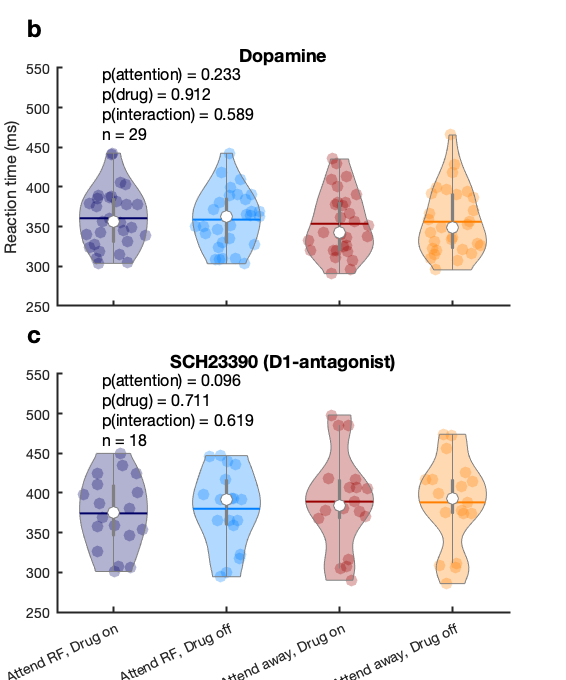

mfactor = 1000; %multiplication_factor
colors = get_colors('att_drug');

ncol = 1;
nrow = length(label_drug);

ylim2plot = [250 550];

[fH, fSet] = plotj_initFig('width', 10, 'height', 12, 'Journal',plot_conventions);

clear legendText h
for idrug = 1:length(label_drug)
    
    idx_rec = strcmpi(recordinglist.Drug, label_drug(idrug));
    %
    subtightplot(nrow, ncol, idrug, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
    plotj_initAx(fSet, 'axlabel', idrug + 1, 'axlabelDisplacement', [0.07, 0.01]);
    hold on
    
    title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)

    % plot errorbar
    iattDrug = 0;
    [RT_table,RT_mat,colors_mat] = deal([]);
    for iatt = 1:2
        for idrug_in = 1:2
            iattDrug = iattDrug+1;
            
            y = squeeze(mean(RT.RT(idx_rec,idrug_in,abs(idx_attention_cond-2)==iatt),3)) * mfactor;
            text_legend{iattDrug} = sprintf('%s, %s', label_attention{iatt}, label_drug_onoff{idrug_in});
            n = length(find(idx_rec));
            rec = (1:n)';
            cond = repmat(iatt,n,1);
            drug = repmat(idrug_in,n,1);
            RT_table = [RT_table ; table(rec,y,cond,drug,'VariableNames',{'recording','RT','attention','drug'})];
            RT_mat = [RT_mat, y];
            colors_mat = [colors_mat ; squeeze(colors(iatt,idrug_in,:))'];
            
        end
    end
    
    RT_table.attention = categorical(RT_table.attention);
    RT_table.drug = categorical(RT_table.drug);
    
    v = violinplot(RT_mat, text_legend, 'ShowMean', true);
    for iv = 1:length(v)
        v(iv).ViolinColor = colors_mat(iv,:);
    end
    
    % do stats
    % check with lme
    lme = fitlme(RT_table,['RT ~ 1 + (1|recording)'], 'DummyVarCoding', 'effects');% fit constant
    lme2 = fitlme(RT_table,['RT ~ attention + (1|recording)'], 'DummyVarCoding', 'effects'); % fit linear model with attention condition
    lme3 = fitlme(RT_table,['RT ~ attention + drug + (1|recording)'], 'DummyVarCoding', 'effects'); %  fit linear model with states
    lme4 = fitlme(RT_table,['RT ~ attention + drug + attention:drug + (1|recording)'], 'DummyVarCoding', 'effects'); % fit interaction
    
    [BETA,BETANAMES,STATS] = fixedEffects(lme4);
    
    % compare the model fits
    comp1 = compare(lme, lme2, 'CheckNesting',true); % compare linear to constant
    comp2 = compare(lme2, lme3, 'CheckNesting',true); %
    comp3 = compare(lme3, lme4, 'CheckNesting',true); %
    
    [p_fdr, p_masked] = FDR( [comp1.pValue(2) comp2.pValue(2) comp3.pValue(2)], 0.05);
    
    pstring = get_significance_strings([STATS.pValue(2:end)], 'rounded', 0, 'factorstring', {'attention', 'drug', 'interaction'});
    
    pstring{4} = ['n = ' num2str(length(find(idx_rec)))];
    
    ylim(ylim2plot)
    
    % plot text indicating number of units
    set(gca, 'Units', 'normalized');
    
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.1);
    y_pos = get_value_range(tmp_y, 0.85);
    
    text(x_pos, y_pos, pstring, 'FontSize', fSet.Fontsize_text)
    if idrug==1
        ylabel('Reaction time (ms)', 'FontSize', fSet.Fontsize_text)
    end
    
    if idrug == length(label_drug)
        set(gca, 'xticklabelRotation', 25)
    else
        set(gca, 'xticklabel', '')
    end
end

## pupil timecourse

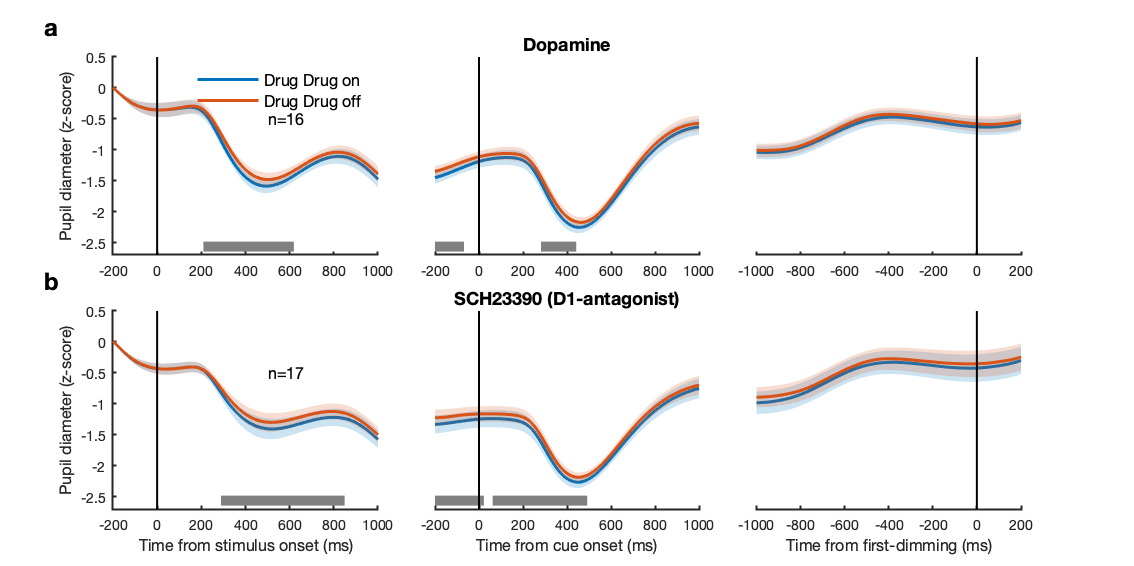

events = {'stim', 'cue', 'dim'};
xlabel_event = {'Time from stimulus onset (ms)', 'Time from cue onset (ms)', 'Time from first-dimming (ms)'};
xlim2use = {[-200 1000], [-200 1000], [-1000 200]};
ylim2use = [-2.7 0.5];

ncol = length(events); % events
nrow = 2;%length(label_drug)-1;

timewinsize = 200;
timestep = 10;

[fH, fSet] = plotj_initFig('width', 20, 'height', 10, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap ./ [1 2];
clear ax h legendText
iplot = 0;
for idrug = 1:nrow
    
    for ievent = 1:length(events)
        iplot = iplot+1;
        
        
        [pupil_timeseries, reclist] = get_population_data(recordinglist, 'pupil_timeseries', path_data, events{ievent});
        
        if nrow==length(label_drug)
            idx_rec = strcmpi(reclist.Drug, label_drug(idrug));
        else
            idx_rec = true(height(reclist),1);
        end
        nrecs = length(find(idx_rec));
        
        pupil2plot = squeeze(nanmean(pupil_timeseries.pupil(idx_rec,:,:,:),3));
        time = pupil_timeseries.time*1000;
        
        timecenters = time(1):timestep:time(end);
        p_drug = NaN(1,length(timecenters));
        
        clear legendText
        
        h_ax = subtightplot(nrow, ncol, iplot, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin);
        if ievent==1
            plotj_initAx(fSet, 'axlabel', idrug, 'axlabelDisplacement', [0.07, 0.01]);
        else
            plotj_initAx(fSet);
        end
        hold on
        
        if (ievent~=1)
            axh = get(gca);
            axh.YTick = [];
            axh.YAxis.Visible = 'off'; % remove y-axis
        end
        
        ilegend = 0;
        
        for idrug_in = 1:2
            ilegend = ilegend+1;
            
            y = squeeze(nanmean(pupil2plot(:,idrug_in,:),1));
            y_err = squeeze(nanstd(pupil2plot(:,idrug_in,:),[],1))/sqrt(size(pupil2plot,1));
            
            h(ilegend) = boundedline(...
                time, ...
                y, ...
                y_err, ...
                'alpha', 'cmap', fSet.colors(idrug_in,:));
            set(h(ilegend), 'LineWidth', fSet.LineWidth)
            
            text_legend{ilegend} = sprintf('Drug %s', label_drug_onoff{idrug_in});
            
        end
        
        for itc = 1:length(timecenters)
            
            timewin = timecenters(itc) + [-timewinsize/2 timewinsize/2];
            idx_time = dsearchn(time(:), timewin(:));
            
            tmp_data = squeeze(nanmean(pupil2plot(:,:,idx_time(1):idx_time(2)),3));
            
            p_drug(itc) = compare_means(tmp_data(:,1), tmp_data(:,2), 1, 'rank');
        end
        
        [p_fdr, p_masked] = FDR( p_drug, 0.05);
        plotj_brokenVector(timecenters, ylim2use(1)*0.95, p_masked, 'linewidth', 5, 'color', [0.5 0.5 0.5]);
        
        if iplot==1
            hleg = legend(h, text_legend, 'autoupdate', 'off', 'FontSize', fSet.Fontsize_text, 'Box', 'Off');
        end
        xlim(xlim2use{ievent})
        ylim(ylim2use)
        plot([0 0], ylim, 'k','linew',1)
        
        if ievent==1
            ylabel('Pupil diameter (z-score)', 'FontSize', fSet.Fontsize_text)
        end
        if idrug==nrow
            xlabel(xlabel_event{ievent}, 'FontSize', fSet.Fontsize_text)
        end
        
        if ievent~=1
            set(gca,'yticklabel',[])
        end
        if nrow>1
            if ievent==2
                title([label_drug{idrug} label_drug_ext{idrug}], 'FontSize', fSet.Fontsize_title)
            end
        end
        
        if ievent==1
            text(h_ax, 500, -0.5, sprintf('n=%d',nrecs), 'FontSize', fSet.Fontsize_text)
        end
        
    end
end

## Pupil drug/no drug, scatter

colors = get_colors('drug');

events = {'baseline', 'stim', 'cue', 'dim'};
event_title = {'Baseline','Stimulus evoked','Cue evoked','First-dimming'};

ncol = length(events); % events
nrow = 1;

xtext = [22 22];
ytext = [-0.45 -0.32];


[fH, fSet] = plotj_initFig('width', 20, 'height', 10, 'Journal',plot_conventions);
fSet.subplotGap = fSet.subplotGap/1.5;
clear ax h legendText

[P, h_text] = deal(NaN(length(events), length(label_drug)));
for ievent = 1:length(events)
    
    [pupil, reclist] = get_population_data(recordinglist, 'pupil_windows', path_data, events{ievent});
    
    axlim = [];
    
    subtightplot(nrow, ncol, ievent, fSet.subplotGap, fSet.subplotMargin, fSet.subplotMargin)
    plotj_initAx(fSet, 'axlabel', ievent+2, 'axlabelDisplacement', [0.05, 0.13]);
    hold on
    title(event_title{ievent}, 'FontSize', fSet.Fontsize_title)
    
    % significance testing
    text_p = cell(length(label_drug),1);
    for idrug = 1:length(label_drug)
        
        idx_rec = strcmpi(reclist.Drug, label_drug(idrug));
        
        pupil2plot = squeeze(nanmean(pupil.pupil(idx_rec,:,:),3));
        
        P(ievent,idrug) = compare_means(pupil2plot(:,1), pupil2plot(:,2), 1, 'rank');
        
        text_p{idrug} = get_significance_strings(P(ievent,idrug), 'rounded', 0);
        
        text_legend{idrug} = sprintf('%s (n=%d)', label_drug{idrug}, length(find(idx_rec)));
        
        % mean difference
        delta_data = pupil2plot(:,2)-pupil2plot(:,1);
        
        % effect size
        d = computeCohen_d(pupil2plot(:,2), pupil2plot(:,1), 'paired');
        
        % print result
        fprintf('%s: %s, delta-%s %1.2f +- %1.2f, %s, Cohens''s d = %1.2f\n', ...
            'PUPIL', ...
            label_drug{idrug}, ...
            'pupil', ...
            mean(delta_data), ...
            std(delta_data)/sqrt(length(find(idx_rec))), ...
            text_p{idrug}, ...
            d)
        
    end
    
    
    pupil2plot = squeeze(nanmean(pupil.pupil,3));
    h = plotj_scatter(pupil2plot, ...
        'dataIndex', idx_rec+1, ...
        'Markersize', markersize, 'markerStyle', {'o','s'}, ...
        'MarkerEdgeColor', colors, 'MarkerFaceColor', colors, ...
        'MarkerEdgeAlpha', [0.5 0.5] ,'MarkerFaceAlpha', [0.5 0.5]);
    
    %     set(gca,'ydir','reverse')
    axis square
    tmp_x = get(gca,'xlim');
    tmp_y = get(gca,'ylim');
    
    x_pos = get_value_range(tmp_x, 0.6);
    
    for idrug = 1:length(label_drug)
        
        y_pos = get_value_range(tmp_y, 0.2-0.1*(idrug-1));
        
        h_text(ievent,idrug) = text(x_pos, y_pos, text_p{idrug}, 'FontSize', fSet.Fontsize_text, 'color', colors(idrug,:));
    end
    
    if ievent==1
        ylabel({'Drug (z-score)'}, 'FontSize', fSet.Fontsize_text)
    end
    xlabel({'No drug (z-score)'}, 'FontSize', fSet.Fontsize_text)
    
    if ievent==4
        hleg = legend(h, text_legend, 'FontSize', fSet.Fontsize_text, 'Box', 'Off', 'Location', 'NorthEast');
        hleg.Position = hleg.Position + [0.05 0.3 0 0];
    end
    
end

PUPIL: Dopamine, delta-pupil 0.02 +- 0.04, p = 0.821, Cohens's d = 0.13
PUPIL: SCH23390, delta-pupil 0.01 +- 0.05, p = 0.890, Cohens's d = 0.04
PUPIL: Dopamine, delta-pupil 0.10 +- 0.02, p < 0.001, Cohens's d = 1.09
PUPIL: SCH23390, delta-pupil 0.10 +- 0.03, p = 0.004, Cohens's d = 0.79
PUPIL: Dopamine, delta-pupil 0.08 +- 0.03, p = 0.051, Cohens's d = 0.66
PUPIL: SCH23390, delta-pupil 0.07 +- 0.03, p = 0.031, Cohens's d = 0.62
PUPIL: Dopamine, delta-pupil 0.05 +- 0.03, p = 0.193, Cohens's d = 0.37
PUPIL: SCH23390, delta-pupil 0.06 +- 0.03, p = 0.023, Cohens's d = 0.54


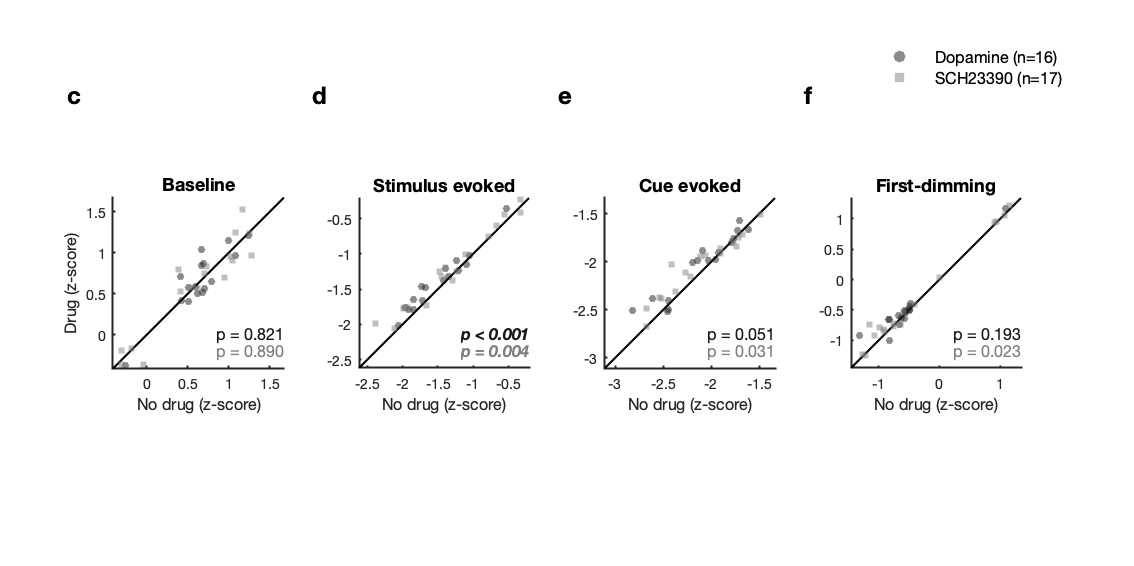


[p_fdr, p_masked] = FDR(P, 0.05);
plotj_text_emphasise(h_text, p_masked, 'italic');
plotj_text_emphasise(h_text, p_masked, 'bold');